# Optimização do servomecanismo de um disco rígido

#### Cadeira: Modelação e Simulação 2º Semestre 2019/2020

#### Trabalho de Laboratório nº 2

#### Alunos: Daniel Leitão 90042 - João Almeida 90119

#### Grupo: 2

#### Turno: Quarta-Feira 8:30-10:30

#### Docente: Alexandre Bernardino

## Estratégia adotada na aproximação ao problema

**Objetivo do trabalho: **comparar diferentes estratégias para controlo do braço da unidade de disco.

De modo a cumprir o obetivo, separou-se o trabalho em dois polos. A partir dos dados obtidos no enunciado resolveu-se representar o sistema em espaço de estados, contínuo do tempo.


$$\dot{x}=Ax+Bu\\
y=Cx+Du
$$


Deste modo, dividiu-se o código numa estrutura relativa ao sistema, 

type("set_system.m")


function s = set_system(b)
    % Declares system struct
    
    s = struct('name', 'Disco Rígido');
    
    if nargin == 0  % default value for friction
        b = 0;  % friction
    end

    A = [0 1; 0 -b]; B = [0; 1]; C = eye(2); D = 0;	% $\ddot{y} = u - b\dot{y}$
    s.X0 = [1;0];	% initial condiction
    s.sys = ss(A,B,C,D);	% steady-state
    s.Gz = tf(s.sys);	% continuous-time transfer function.
end



s = set_system();

numa estrutura relativamente aos controladores,

type("set_controller.m")


function s = set_controller()
    % Declares system struct
    
    s = struct('name', 'Controlador');
    
    s.K = 10000;	% gain pre-saturation
    s.y = 0;	% output
    s.sample_time = 1e-3;	% sample time
    s.q = 10;	% input decision based on question number  
    s.yl = 1e-2;	% question 10 saturation levels
    s.lz = 0; % activate linear zone exclusively
    s.ref = timeseries(0);	% input reference for position y1 
end


c = set_controller();

e numa estrutura relativamente ao sinal de referência, que serve como guia para a posição da cabeça do braço.

type("set_signal.m")


function s = set_signal(T, alpha, beta, U1, U2, n1, n2, ctrl)
    % Declares input sinal struct
    
    s = struct('name', 'Entrada');
    
    s.alpha = alpha_bounds(alpha);	% relation between T1 and T2: T1 = $\alpha T2$
    s.beta = beta_bounds(beta);	% curve efect of the u(t) up and donw range
    s.U = [U1 U2];	% max range of $u_1$(t) and $u_2$(t)
    s.N = [n1 n2];	% number of ponits of $u_1$(t) and $u_2$(t)
    s.T = T;
    
    if ctrl == 1 % para obter o sinal conforme a alínea 6
        s.T = max([sqrt(2*(1+s.beta)*(1+s.alpha)), sqrt(2*(1+s.beta)*(1+s.alpha)/s.alpha)]);	% $T_{minimo}$ calculated from question 6
        s.U(1) = alpha*s.U(2);
    end
    
end


As funções auxilares (alpha_bounds e beta_bounds) encontram-se explicadas nos anexos.

Em suma, organizando o código nas três estruturas a cima faladas, é possível tornar o programa menos redundante.

## (2) e (3) - Estudo do impulso Protótipo

Numa primeira abordagem ao problema, resolveu-se estudar o comportamento do sistema em malha aberta, para tal começou-se por simular sinais de entrada. Foi sugerido começar com uma função que gerasse um impulso protótico, resultante da convulsão de um impulso rectangular com um impulso triangular. Por outras palavras, o impulso protótico assemelha-se a um impulso retangular porém mudança de valores nas extremidades é contínua, sendo controlada a sua suavidade (e consequentemente, a extensão) pelo parâmetro signal.beta.

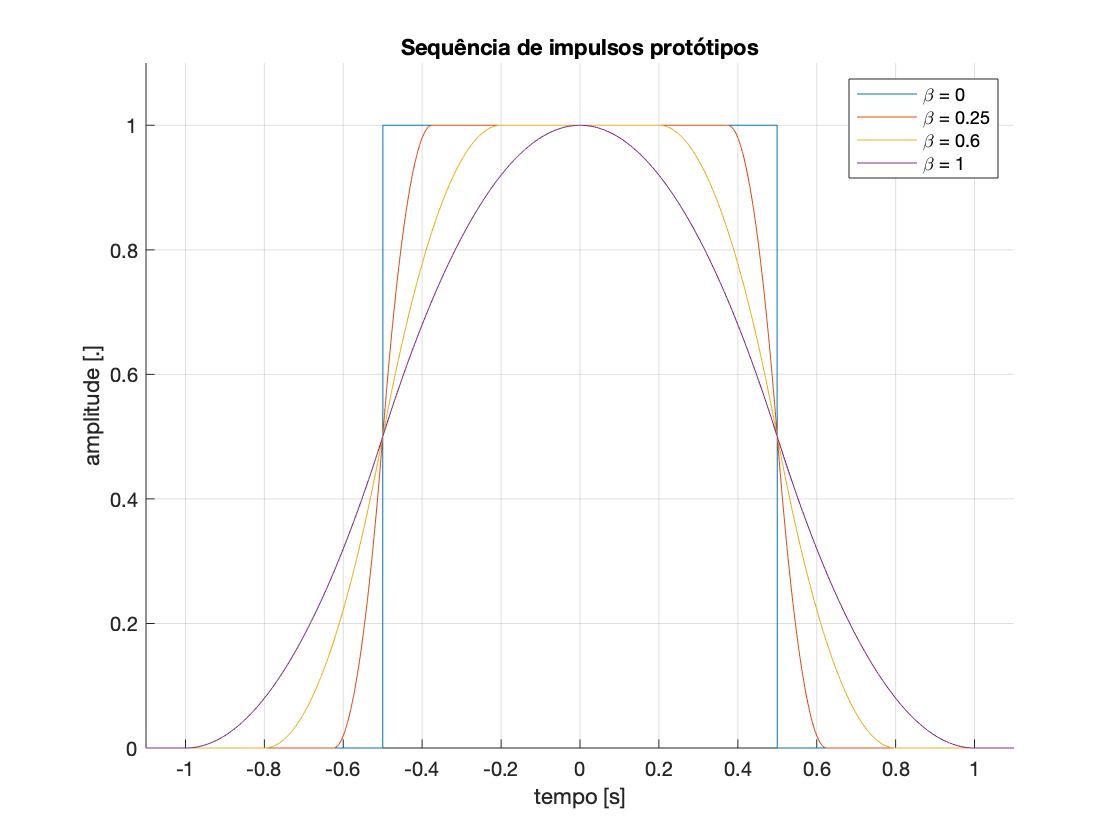

beta_vect = [0 0.25 0.60 1];
label_vect = strings(1,4);

figure();clf; grid on; hold on;

for i = 1:4
    v_t = linspace(-2,2,10001);
    v_y = u_impulse(v_t, beta_vect(i));
    label_vect(i) = ['\beta = ' num2str(beta_vect(i))];
    plot(v_t,v_y);
end

axis([-1.1 1.1 0 1.1]);
xlabel('tempo [s]');
ylabel('amplitude [.]');
legend(label_vect);
title('Sequência de impulsos protótipos');

A função auxilar (u_impulse) encontra-se explicada nos anexos.

De seguida é simulado o impulso $u(t)$, resultante da sequência de dois impulsos protótipos com valores de amplitude (U) com sinais contrários. Desta forma é introduzida uma segunda dimensão na entrada, que permite uma instrução com sentido contrário.

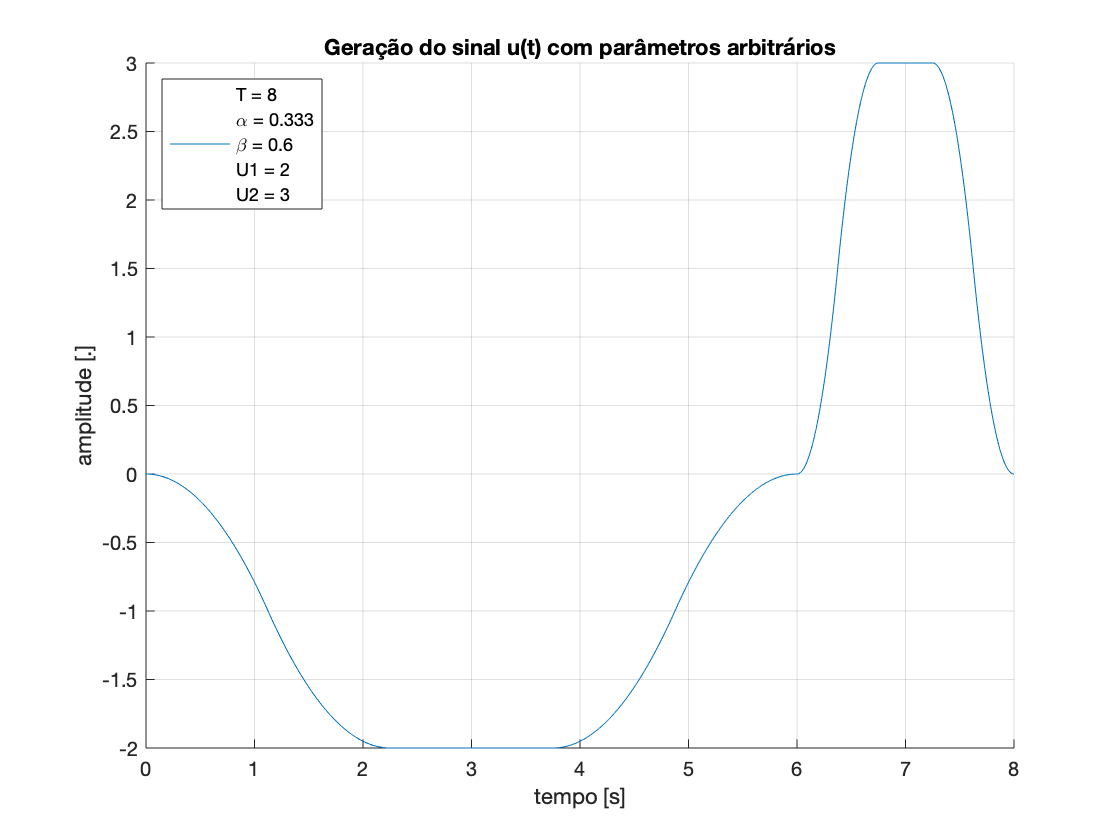

signal = set_signal(8, 1/3, 0.6, 2, 3, 3000, 1000, 0);

figure();clf; grid on; hold on;

[v_t, v_y] = u_generator(signal);

plot(v_t,v_y);
legend(['T = ' num2str(signal.T) '\newline\alpha = ' num2str(signal.alpha, '%.3f') ...
    '\newline\beta = ' num2str(signal.beta) '\newlineU1 = ' num2str(signal.U(1)) ...
    '\newlineU2 = ' num2str(signal.U(2))], 'Location', 'NorthWest');
xlabel('tempo [s]');
ylabel('amplitude [.]');
title('Geração do sinal u(t) com parâmetros arbitrários');

A função auxilar (u_generator) encontra-se explicada nos anexos

## Simulação do movimento do braço - SIMULINK

**Workspace do SIMULINK**

Ao sintetizar ambos os controladores no mesmo workspace do SIMULINK tornou-se o progama menos ambíguo, seguindo o objetivo traçado anteriormente. Desta forma, ultilizou-se um multiplexer à entrada do controlador do sistema, com a variável de decisão signal.q, permitindo escolher analisar o sistema em malha aberta (signal.q = 7), ou em malha fechada. Nesta última simulação, ainda é possível decidir usar o controlador relativamente à pergunta 8 (signal.q = 8) ou relativamente à pergunta 10 (signal.q = 10), que conta ainda com outro parâmetro adicional (signal.yl) para definir os ramos da função "subsys" ativos, algo explorado mais adiante.

%open_system('disco_rigido');
%close_system

## (7) - Simulação em Malha Aberta

Em prol de testar o controlador em malha aberta gerou-se um sinal que excitasse o sistema mas que impusesse que a velocidade final seja nula, ou seja: $\int_{-\infty}^{\infty}\dot{y}(t)dt = 0$. Desta forma, resolvido analiticamente nas questão 4-7, estabelece-se relações entre os subsinais de $u(t)$ tal que:  $U_1 = - \alpha U_2.$

Tendo em conta as restrições do enunciado , descobriu-se o valor correspondente a $\alpha $, para que o tempo de simulação fosse minímo tendo em conta que $|U_{1,2}| < 1$.

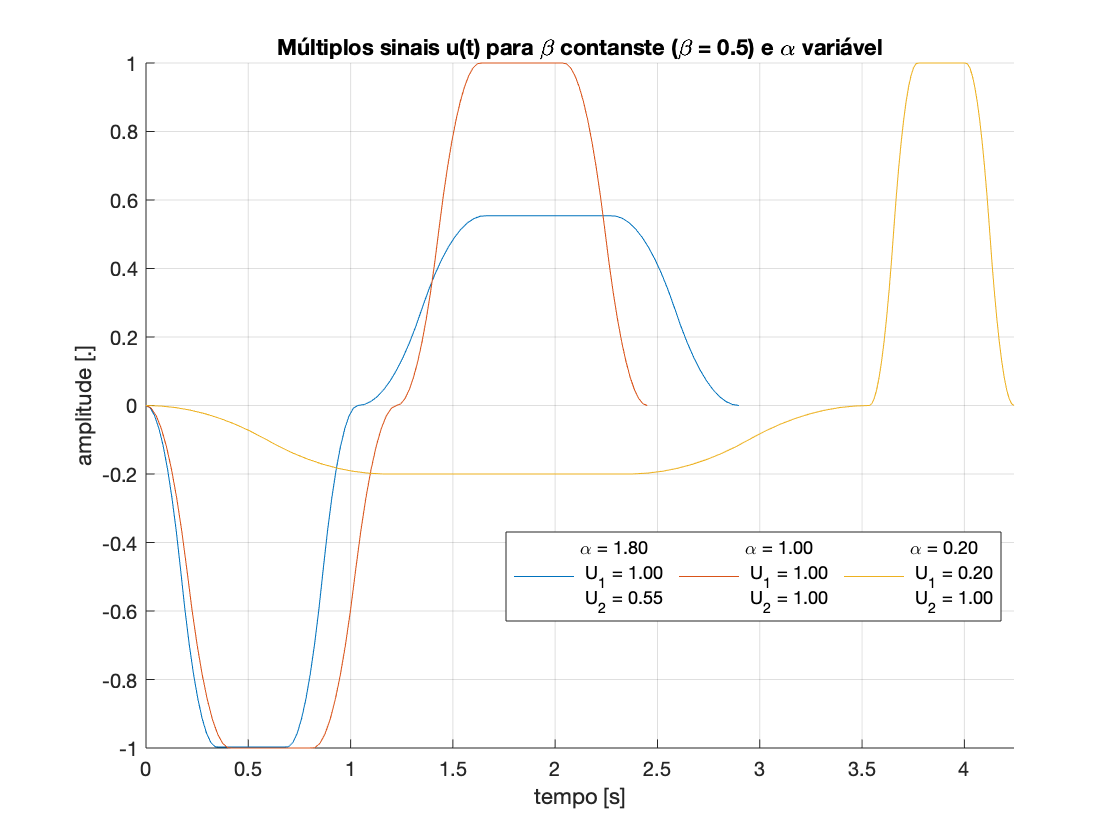

u2_vect = [0.554 1 1 ];
alpha_vect = [1.8 1 0.2];
label_vect = strings(1,3);
signal = set_signal(-1, 0, 0.5, -1, -1, 50, 60, 0);    % set signal \beta and Ns
u_ger = zeros(3,sum(signal.N)-1);
t_ger = zeros(3,sum(signal.N)-1);
t_min = zeros(3,1);

figure();clf; grid on; hold on;

for i = 1:3
    signal = set_signal(-1, alpha_vect(i), 0.5, -1, u2_vect(i), 50, 60, 1);
    t_min(i) = signal.T; % min T , according question 6 
    [t_ger(i,:),u_ger(i,:)] = u_generator(signal);
    label_vect(i) = ['\alpha = ' num2str(alpha_vect(i), '%.2f') '\newline U_1 = ' ...
        num2str(alpha_vect(i)*u2_vect(i), '%.2f') '\newline U_2 = ' num2str(u2_vect(i), '%.2f')];
    plot(t_ger(i,:),u_ger(i,:));
end

axis([0 signal.T -1 1]);
xlabel('tempo [s]');
ylabel('amplitude [.]');
legend(label_vect,'NumColumns', 3, 'Location', 'best');
title('Múltiplos sinais u(t) para \beta contanste (\beta = 0.5) e \alpha variável');

A partir da fórmula obtida na questão 6, é calculado o tempo minímo. O cálculo acontece quando estamos presentes nas condições de equilíbrio (último parâmetro da função set_signal é 1). Para os diversos pares de valores ($\alpha, \beta
$), obteve-se o tempo mínimo (segundos) que o sistema demora a responder para que se cumpram as condições enunciadas.

disp(t_min)

    2.8983
    2.4495
    4.2426



Como previsto teoricamente, o valor de \alpha que traduz num menor tempo de simulação é \alfa = 1.

Para cada impulso anterior e em condições de atrito nulo, obteve-se as respostas seguintes do sistema para a posição do cabeça de leitura e posição do braço:

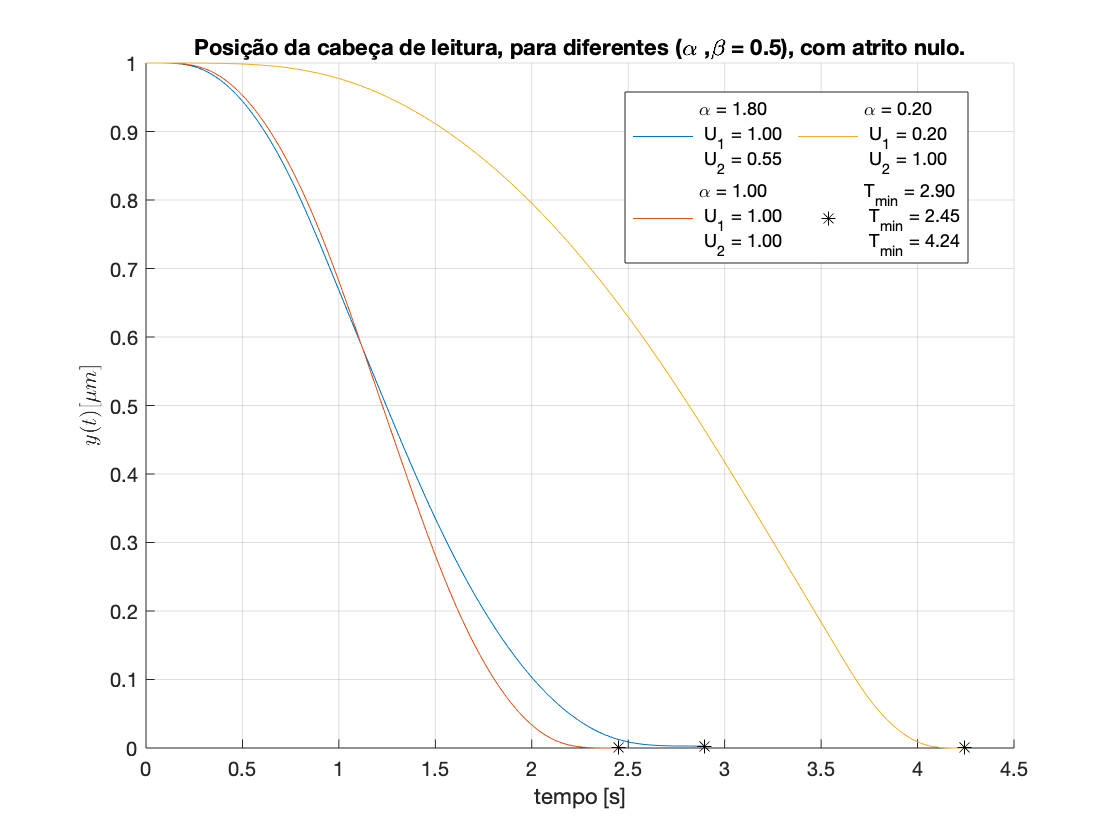

figure(1);clf; grid on; hold on;
figure(2);clf; grid on; hold on;

s = set_system(0);
c = set_controller();
c.q = 7; % question
coord = zeros(2,6);
p = zeros(2,3);


for i = 1:3
    signal.u = timeseries(u_ger(i,:)',t_ger(i,:)');
    signal.y = sim('disco_rigido','Stoptime','t_min(i)');
    figure(1)
    p(1,i) = plot(signal.y.y.Time,signal.y.y.Data(:,1));
    coord(1,i) = signal.y.y.Time(end); coord(2,i)=signal.y.y.Data(end,1); % save end point position
    figure(2)
    p(2,i) = plot(signal.y.y.Time,signal.y.y.Data(:,2));
    coord(1,i+3) = signal.y.y.Time(end); coord(2,i+3)=signal.y.y.Data(end,2); % save end point velocity
end

% figure(y1) graph
figure(1);
xlabel('tempo [s]');
ylabel('$y(t) [\mu m]$','interpreter', 'latex');
title('Posição da cabeça de leitura, para diferentes (\alpha ,\beta = 0.5), com atrito nulo.');
pp = plot(coord(1,1:3), coord(2,1:3),'k*');
lpp = ['T_{min} = ' num2str(coord(1,1), '%.2f') '\newline T_{min} = ' num2str(coord(1,2), '%.2f') '\newline T_{min} = ' num2str(coord(1,3), '%.2f')];
l = legend([p(1,1:3) pp], [label_vect lpp]);
l.NumColumns =2; l.Location = 'best';

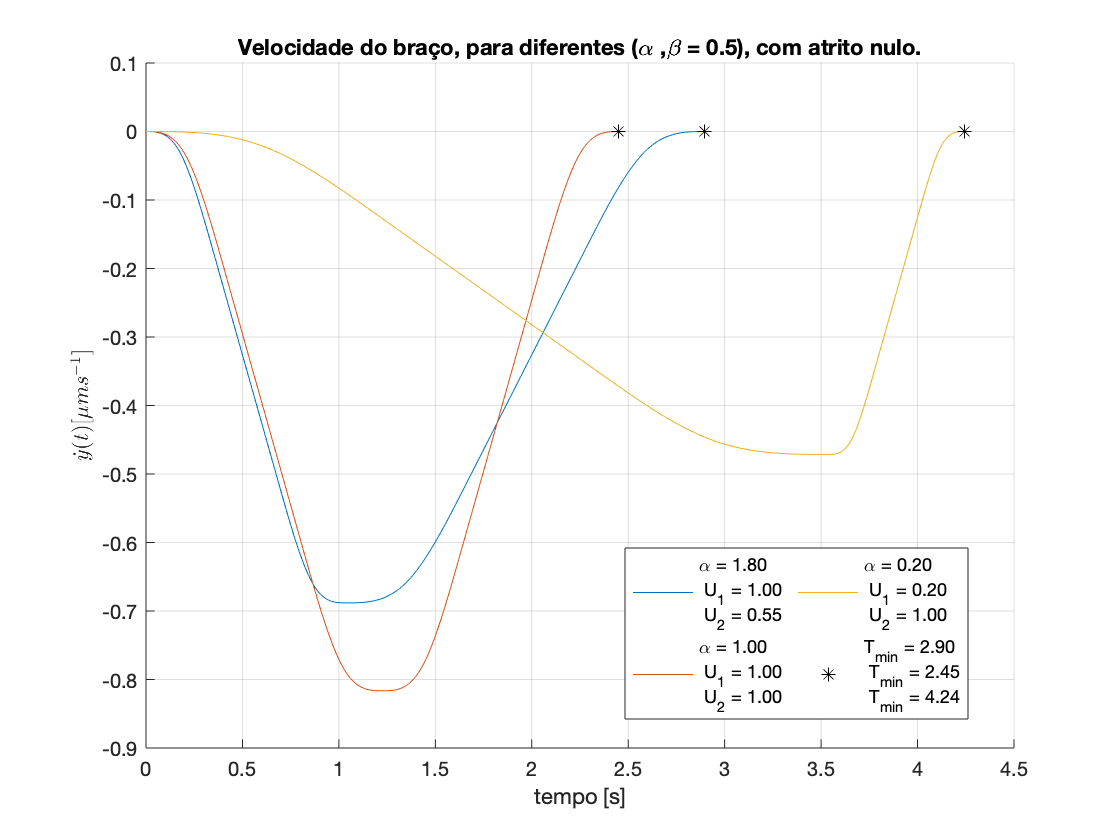


% figure(t2) graph
figure(2);
xlabel('tempo [s]');
ylabel('$\dot{y}(t) [\mu ms^{-1}]$','interpreter', 'latex');
title('Velocidade do braço, para diferentes (\alpha ,\beta = 0.5), com atrito nulo.');
pp = plot(coord(1,4:6), coord(2,4:6),'k*');
lpp = ['T_{min} = ' num2str(coord(1,4), '%.2f') '\newline T_{min} = ' num2str(coord(1,5), '%.2f') '\newline T_{min} = ' num2str(coord(1,6), '%.2f')];
l = legend([p(2,1:3) pp], [label_vect lpp]);
l.NumColumns =2; l.Location = 'best';

Deste modo, analisando a legenda e o gráfico, é possível observar o tempo para que o sistema cumpra as condições especificadas: velocidade nula e posição em 0 (condições sem atrito), o que corresponde com o tempo calculado teoricamente.

A fim de estudar o comportamento do sistema em condições com atrito, alterou-se apenas o coeficiente de atrito para b = 0.025.

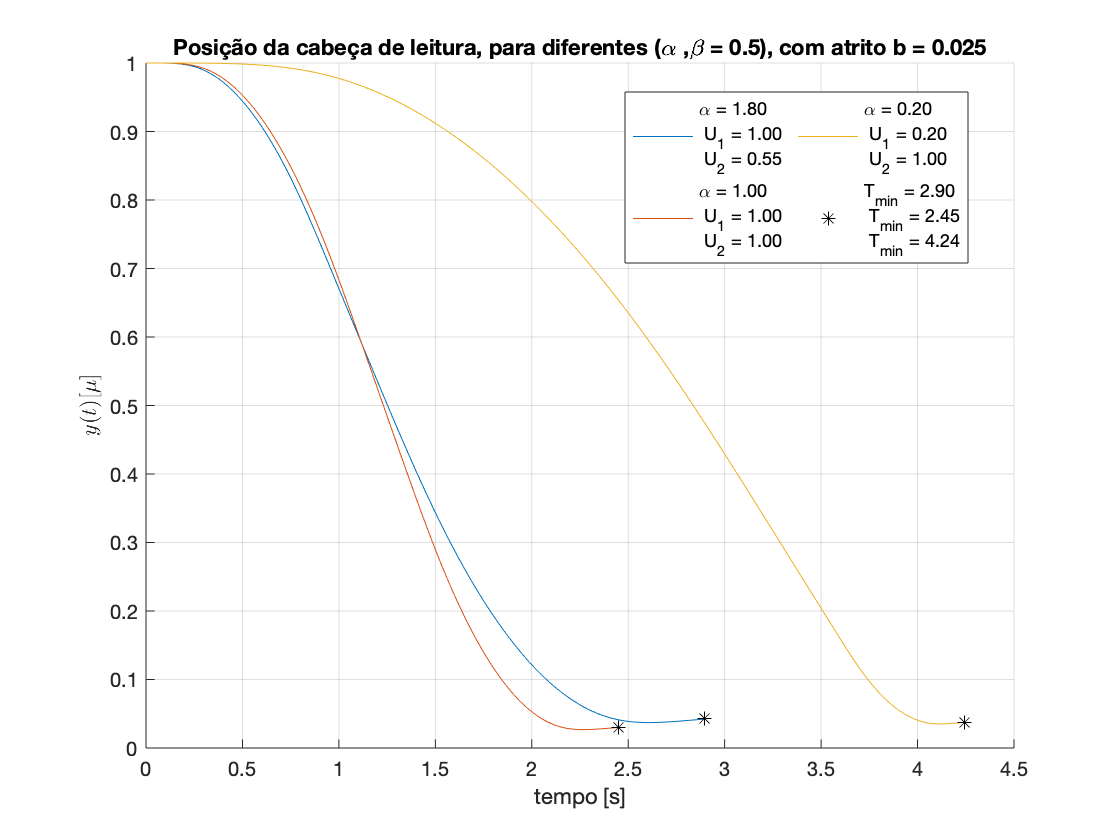

figure(1);clf; grid on; hold on;
figure(2);clf; grid on; hold on;

s = set_system(0.025);
c.q = 7; % question
coord = zeros(2,6);
p = zeros(2,3);

for i = 1:3
    signal.u = timeseries(u_ger(i,:)',t_ger(i,:)');
    signal.y = sim('disco_rigido','Stoptime','t_min(i)');
    figure(1)
    p(1,i) = plot(signal.y.y.Time,signal.y.y.Data(:,1));
    coord(1,i) = signal.y.y.Time(end); coord(2,i)=signal.y.y.Data(end,1); % save end point position
    figure(2)
    p(2,i) = plot(signal.y.y.Time,signal.y.y.Data(:,2));
    coord(1,i+3) = signal.y.y.Time(end); coord(2,i+3)=signal.y.y.Data(end,2); % save end point velocity
end

% figure(y1) graph
figure(1);
xlabel('tempo [s]');
ylabel('$y(t) [\mu]$','interpreter', 'latex');
title('Posição da cabeça de leitura, para diferentes (\alpha ,\beta = 0.5), com atrito b = 0.025');
pp = plot(coord(1,1:3), coord(2,1:3),'k*');
lpp = ['T_{min} = ' num2str(coord(1,1), '%.2f') '\newline T_{min} = ' num2str(coord(1,2), '%.2f') '\newline T_{min} = ' num2str(coord(1,3), '%.2f')];
l = legend([p(1,1:3) pp], [label_vect lpp]);
l.NumColumns =2; l.Location = 'best';

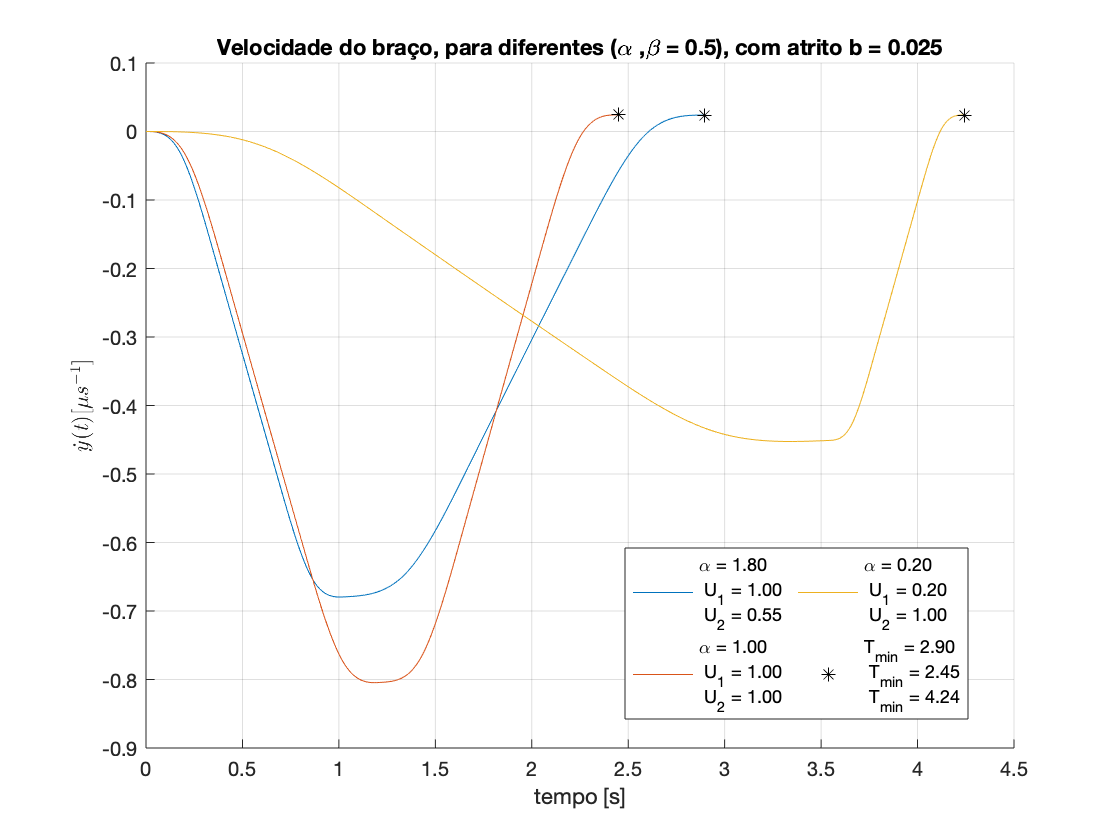


% figure(t2) graph
figure(2);
xlabel('tempo [s]');
ylabel('$\dot{y}(t) [\mu s^{-1}]$','interpreter', 'latex');
title('Velocidade do braço, para diferentes (\alpha ,\beta = 0.5), com atrito b = 0.025');
pp = plot(coord(1,4:6), coord(2,4:6),'k*');
lpp = ['T_{min} = ' num2str(coord(1,4), '%.2f') '\newline T_{min} = ' num2str(coord(1,5), '%.2f') '\newline T_{min} = ' num2str(coord(1,6), '%.2f')];
l = legend([p(2,1:3) pp], [label_vect lpp]);
l.NumColumns =2; l.Location = 'best';

Analisando a resposta do circuito com atrito, observa-se que a posição da cabeça não atinge o ponto 0, pois há uma força contrária ao movimento do braço que não permite o braço atingir a velocidade expectável. Em relação à velocidade, na primeira parte do movimento, o corpo está a acelerar o que implica que a força (u) aplicada tenha sentido contrário à componente do atrito. Numa segunda fase do impulso, até o movimento do braço ter uma mudança no sentido da trajetória está a desacelerar, logo a componente de atrito e a força aplicadas têm o mesmo sentido. Assim, a componente de aceleração vai ser maior quando à inversão do impulso , e portanto o braço vai atingir velocidade nula mais rapidamente. Concluindo, em condições de atrito não nulo, a velocidade do braço retoma o 0 mais rapidamente e permite uma inversão no sentido do movimento, para o mesmo tempo de simulação que em condições sem atrito.

Concluindo, o sistema em malha aberta é insuficiente para um controlo do braço do disco rígido, pois peca na capacidade de corrigir as suas trajetórias *a posteriori, *(i.e. não tem informação suficiente que corriga a sua trajetória,durante o movimento), sendo de uso limitado a situações sem atrito.

## (8) - Estratégia de actuação com impulsos rectangulares/simétricos ±1

O código da ilustração gráfica da entrada do sistema $u(t)$encontra-se nos anexos.

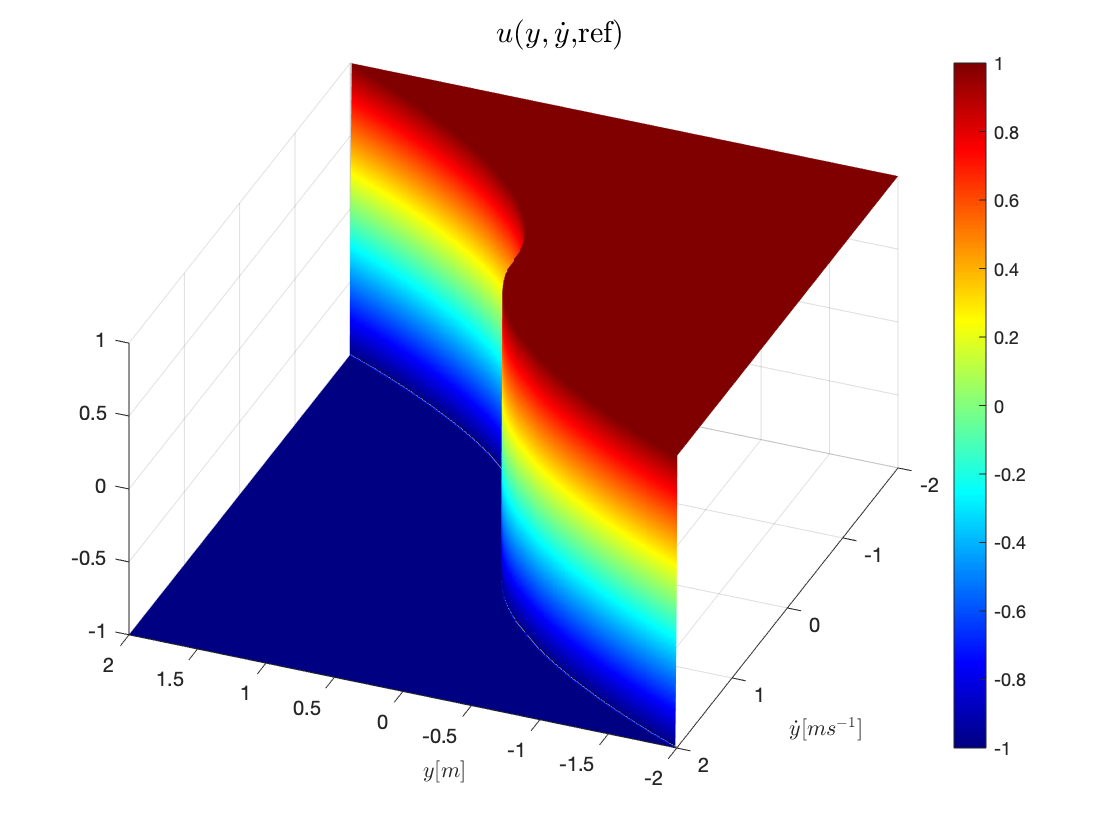

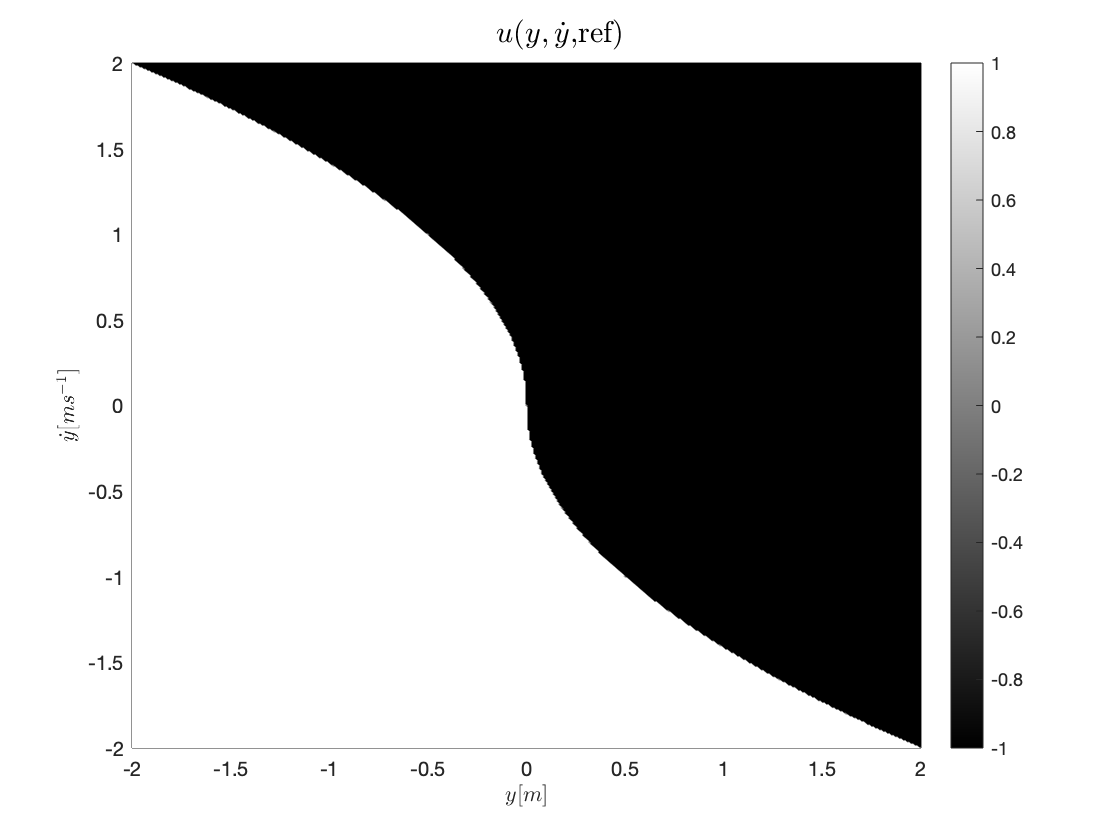

pergunta8

Com vista a um sistema de retroação é proposto um sistema que vai gerando u(t) conforme o estado actual do mesmo. Representa-se duas figuras que mostram explicitamente o sinal de u consoante os valores de $y$, $\dot{y}$ e ref. Nestas pode-se ver que só existem dois valores possíveis para a entrada, que é 1 e -1. Isto implica obviamente que existe uma descontinuidade na fronteira de transição de 1 para -1, e é esta transição brusca que vai estar na origem do fenónemo de *chattering* que irá ser observado ao verificar os gráficos do sinal u(t) gerados por esta nova arquitectura de controlo. No entanto, esta estratégia conduz efectivamente o estado do sistema para zero, pois atrai o estado num dado ponto de partida para um ponto da fronteira de transição, a partir da qual oscilará rapidamente entre uma zona e outra até o estado atingir o zero. Sem atrito, mantém-se as trajectórias parabólicas percorridas pelo sistema conforme expostas na pergunta teórica 5. A sua orientação varia conforme a zona onde o estado se encontra, sendo descendentes e curvadas para a esquerda na zona preta (u = -1) e ascendentes e curvadas para a direita na zona branca (u = 1). A constante (c.K) , antes do bloco de saturação ± foi dimensionada bastante elevada, de modo a que transição entre impulsos com modulo diferente mais dinâmica.

## (9) - Simulação do sistema 

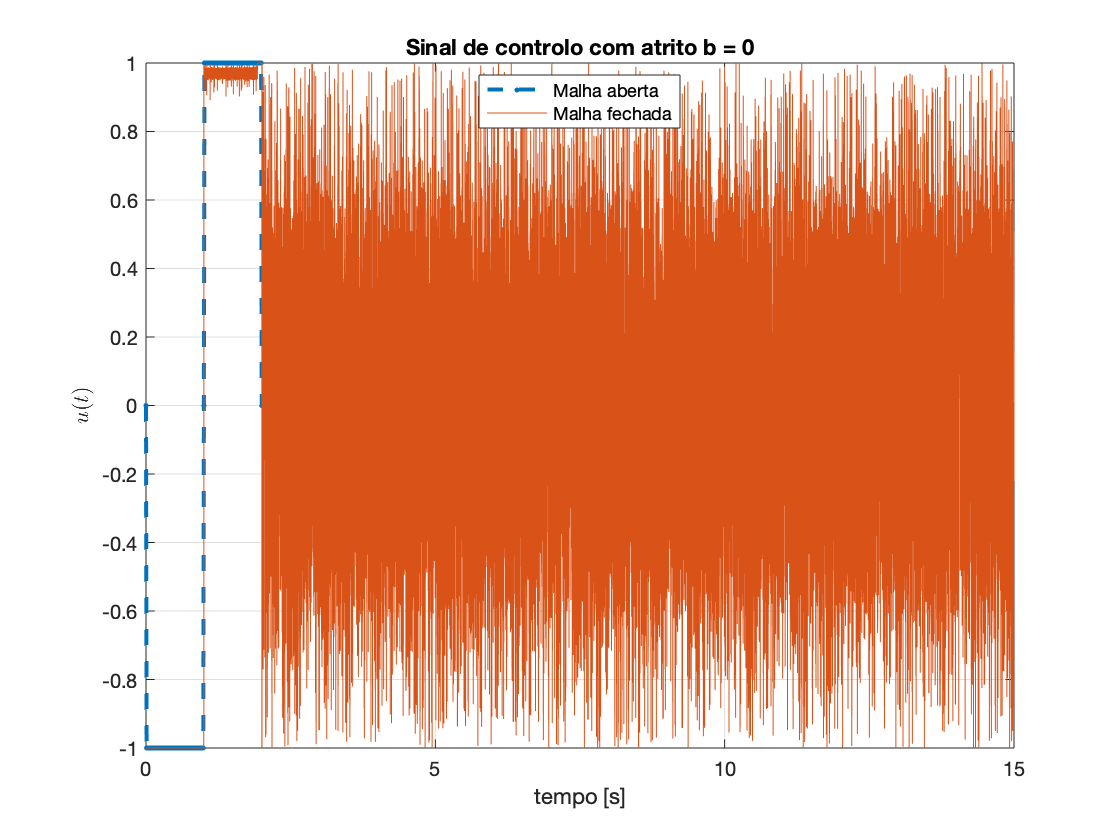

% simulate ±1 impulses with open loop
s = set_system(0);
c = set_controller();
c.q = 7;    % question
signal = set_signal(-1, 1, 0, 0, 1, 100, 100, 1); % u(t)±1
[t_ger,u_ger] = u_generator(signal);
signal.u=timeseries(u_ger',t_ger');
signal.y = sim('disco_rigido');
u_7 = signal.u;
y1_7 = timeseries(signal.y.y.Data(:,1), signal.y.y.Time);
y2_7 = timeseries(signal.y.y.Data(:,2), signal.y.y.Time);

% close lopp
signal.u=timeseries(0);
c.q = 8; % question
q.ref = timeseries(0);
signal.y = sim('disco_rigido');
u_8 = signal.y.u8;
y1_8 = timeseries(signal.y.y.Data(:,1), signal.y.y.Time);
y2_8 = timeseries(signal.y.y.Data(:,2), signal.y.y.Time);

figure();clf;
p7 = plot(u_7,'--.', 'LineWidth', 2); hold on;
p8 = plot(u_8); grid on;
title('Sinal de controlo com atrito b = 0');
ylabel('$u(t)$','interpreter', 'latex');
xlabel('tempo [s]');
legend([p7 p8],{'Malha aberta','Malha fechada'},'Location', 'best')

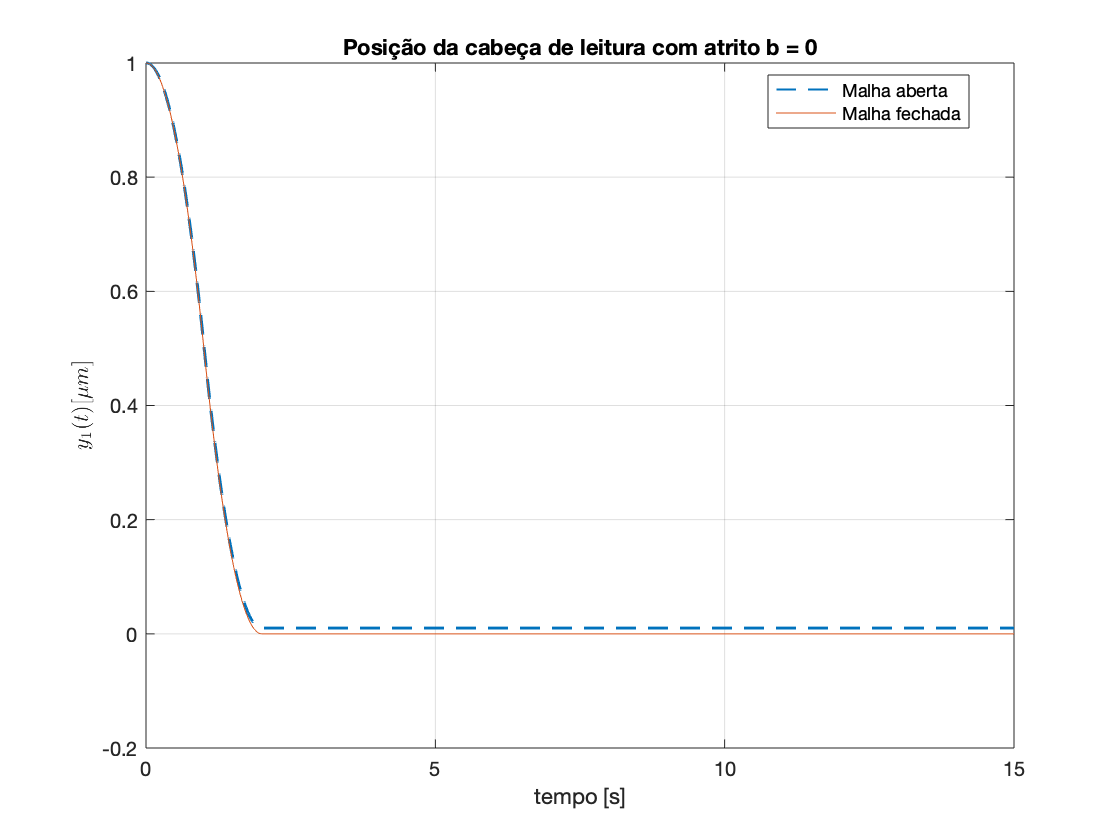


figure();clf;
p7 = plot(y1_7,'--', 'LineWidth', 1); hold on;
p8 = plot(y1_8); grid on;
title('Posição da cabeça de leitura com atrito b = 0')
ylabel('$y_1(t) [\mu m]$','interpreter', 'latex');
xlabel('tempo [s]');
legend([p7 p8],{'Malha aberta','Malha fechada'},'Location', 'best')

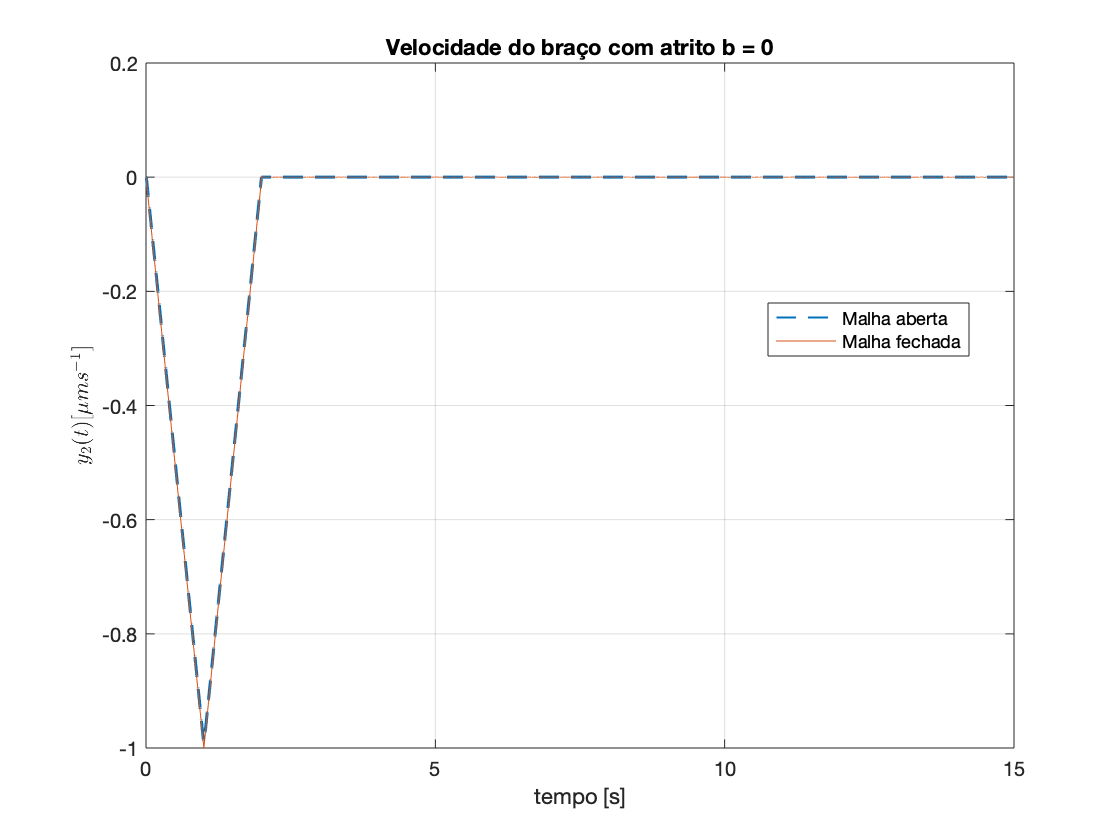


figure();clf;
p7 = plot(y2_7,'--', 'LineWidth', 1); hold on;
p8 = plot(y2_8); grid on;
title('Velocidade do braço com atrito b = 0')
ylabel('$y_2(t) [\mu ms^{-1}]$','interpreter', 'latex');
xlabel('tempo [s]');
legend([p7 p8],{'Malha aberta','Malha fechada'},'Location', 'best')

Conforme já seria de esperar, o sinal u(t) apresenta oscilações bruscas à medida que o estado se aproxima do zero, o que corresponde ao fenómeno de *chattering*. É contudo um incómodo, pois estas oscilações rápidas eventualmente conduzem a danos permanentes do disco rígido, tendo-se que a própria posição do braço do disco irá oscilar muito rapidamente em torno do zero. A origem do fenómeno, conforme referido anteriormente, prende-se com o facto do estado do sistema transitar rapidamente entre os dois valores possíveis para o sinal de controlo (1 e -1), que por sua vez deve-se ao facto do estado acabar a percorrer a fronteira destas zonas (que é descontínua e obriga o estado a "saltitar" entre zonas) à medida que tende para zero. Neste gráficos incluem-se também uma simulação do sistema em malha aberta com o impulso u(t) quadrado (ou seja, $\beta$=0). Verifica-se que os resultados são praticamente iguais, excepto que no caso de malha aberta não se verifica *chattering*, o que é expectável dado que o sinal de controlo já foi previamente gerado. São portanto métodos equivalentes na medida em que os valores que u(t) pode tomar são os mesmos, e a diferença está no método de geração de sinal, que no primeiro caso é por predefinição e no segundo caso é consoante o estado onde o sistema se encontra.

## (10) - Arquitectura de controlo modificada que evita o chattering na entrada

O código da ilustração gráfica da entrada do sistema $u(t)$encontra-se nos anexos.

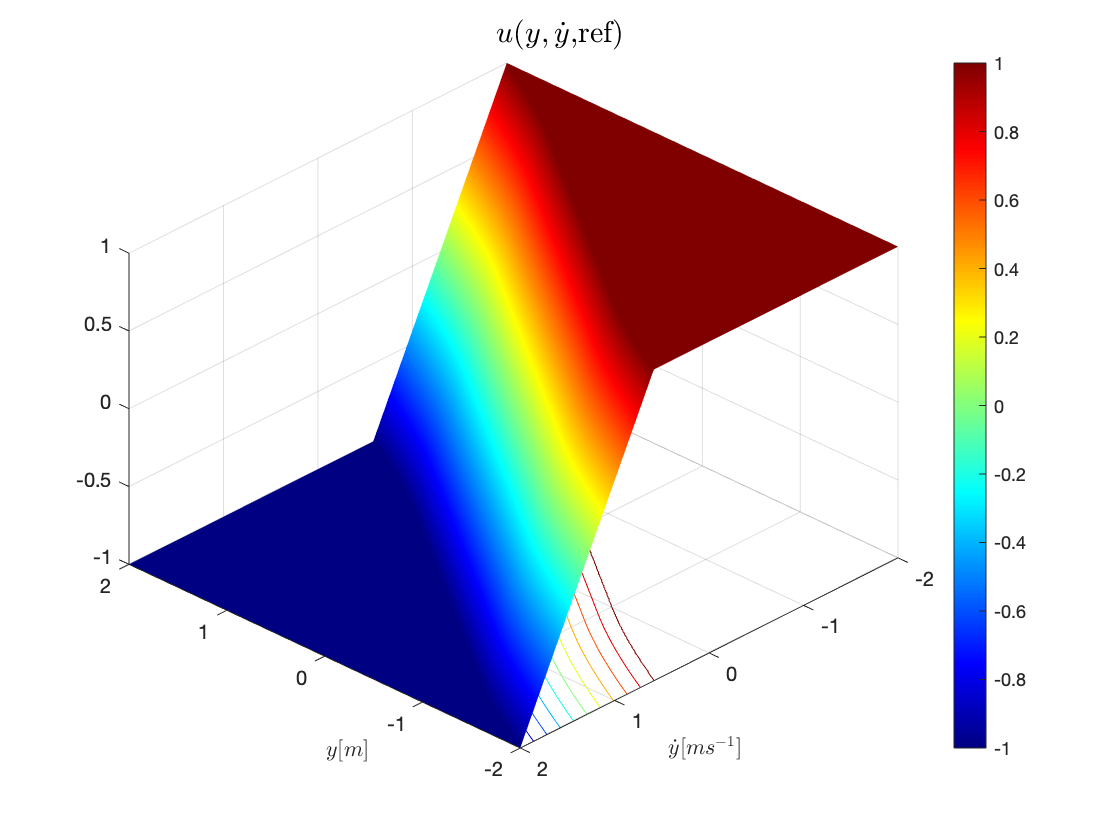

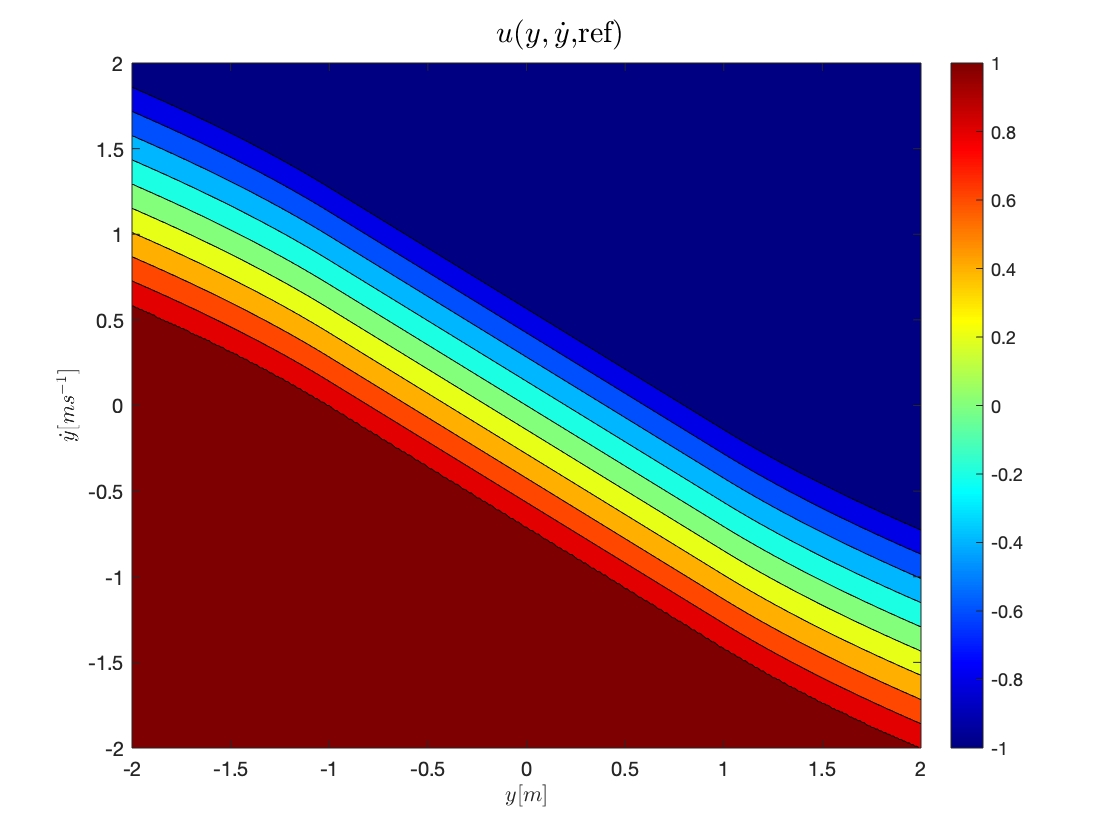

pergunta10

Impleta-se agora um novo método para gerar o sinal de controlo. Tendo em vista o cancelamento do fenómeno de *chattering* previamente observado, inclui-se agora uma zona linear de transição entre as zonas de valor -1 e 1 para u. Esta zona linear substitui a zona fronteiriça que se constatou na arquitectura anterior, sendo agora uma transição "mais suave". Para observar este novo efeito, representam-se duas figuras que mostram explicitamente os novos valores de u para esta situação, consoante os valores de $y$, $\dot{y}$ e ref. A zona linear pode ser encurtada ou extendida recorrendo ao parâmetro "yl"  que toma o valor 1 nesta situação. Este parâmetro representa os limites da zona linear, e faz variar inversamente o declive da mesma. Dimensionou-se "yl" baixo,  de maneira a que o sistema apenas recorresse à zona linear apenas para a transição entre as duas zonas de funcionamento ideal. A redução de "yl" para zero fará com que o sinal u degenere de modo a tornar-se exatamente igual à situação anterior. 

Apesar deste novo sinal de controlo fazer tender o sistema para zero evitando o *chattering,* o estado do sistema tende a demorar mais tempo a atingi-lo (em comparação com o caso anterior) pois a zona linear que substitui a fronteira de descontinuidade antiga contém valores mais pequenos que 1 em módulo (valores máximos para u), o que fará com que o estado evolua mais lentamente à medida que se aproxima do zero, que se encontra precisamente no centro desta zona linear.

## (11) - Comparação dos dois sistemas com cadeia fechada (com/sem *chattering*)

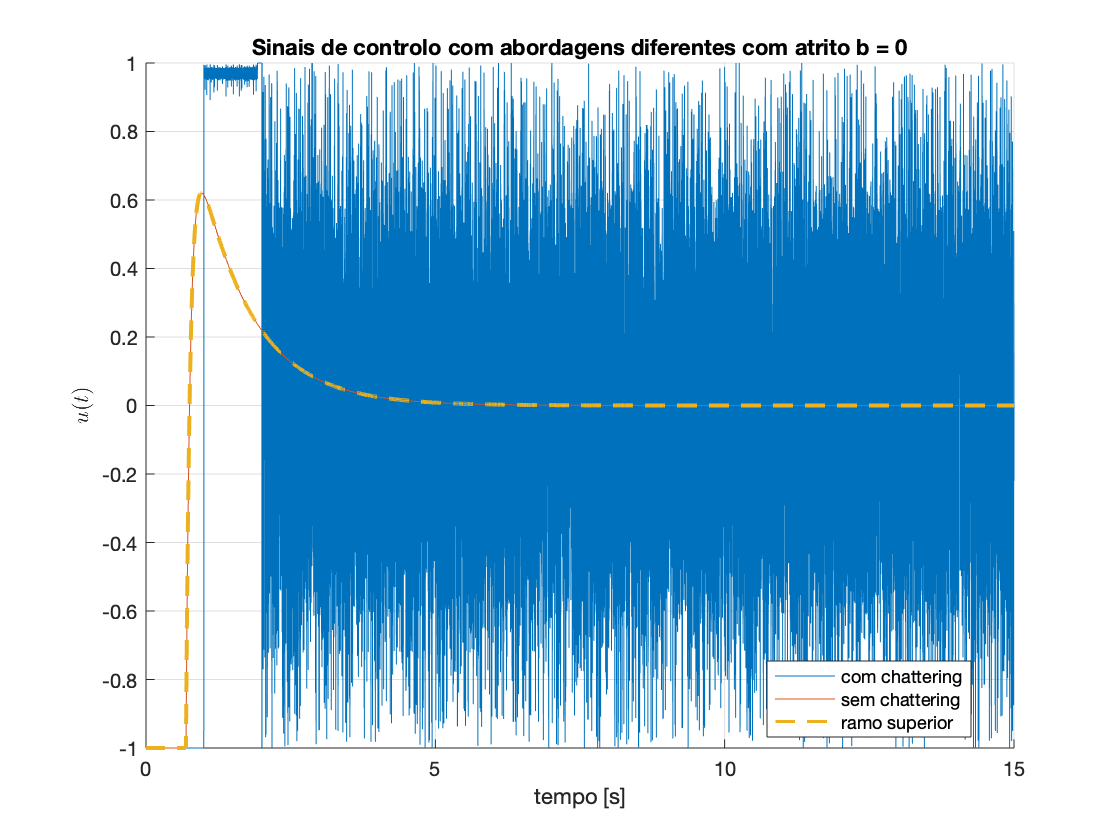

c.q = 10; % question
signal.y = sim('disco_rigido');
u_10 = signal.y.u10;
y1_10 = timeseries(signal.y.y.Data(:,1), signal.y.y.Time);
y2_10 = timeseries(signal.y.y.Data(:,2), signal.y.y.Time);

c.lz = 1; % linear zone only 
signal.y = sim('disco_rigido');
u_10_lzo = signal.y.u10;
y1_10_lzo = timeseries(signal.y.y.Data(:,1), signal.y.y.Time);
y2_10_lzo = timeseries(signal.y.y.Data(:,2), signal.y.y.Time);

figure();clf; hold on; 
plot(u_8);
plot(u_10);
plot(u_10_lzo, '--', 'LineWidth', 1.5); grid on;
title('Sinais de controlo com abordagens diferentes com atrito b = 0')
ylabel('$u(t)$','interpreter', 'latex');
xlabel('tempo [s]');
legend('com chattering','sem chattering', 'ramo superior', 'Location', 'best');

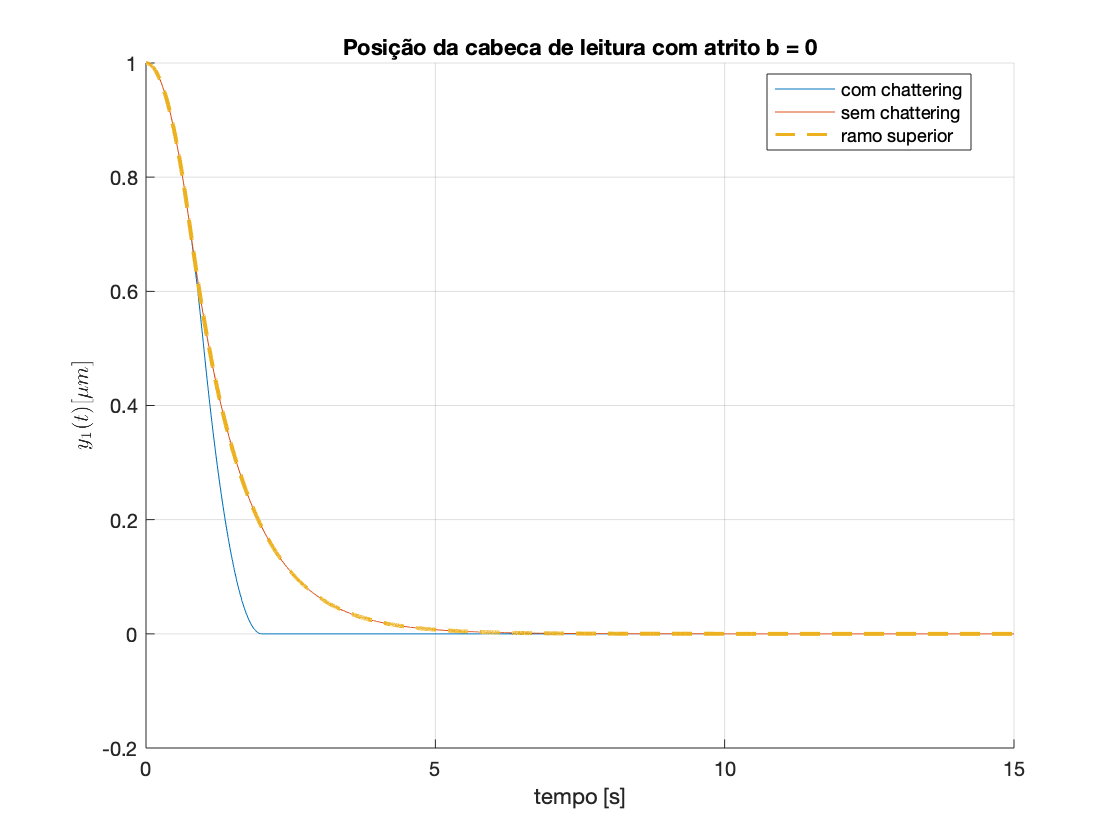


figure();clf; hold on;
plot(y1_8); 
plot(y1_10);
plot(y1_10_lzo, '--', 'LineWidth', 1.5); grid on;
title('Posição da cabeca de leitura com atrito b = 0')
ylabel('$y_1(t) [\mu m]$','interpreter', 'latex');
xlabel('tempo [s]');
legend('com chattering','sem chattering', 'ramo superior', 'Location', 'best');

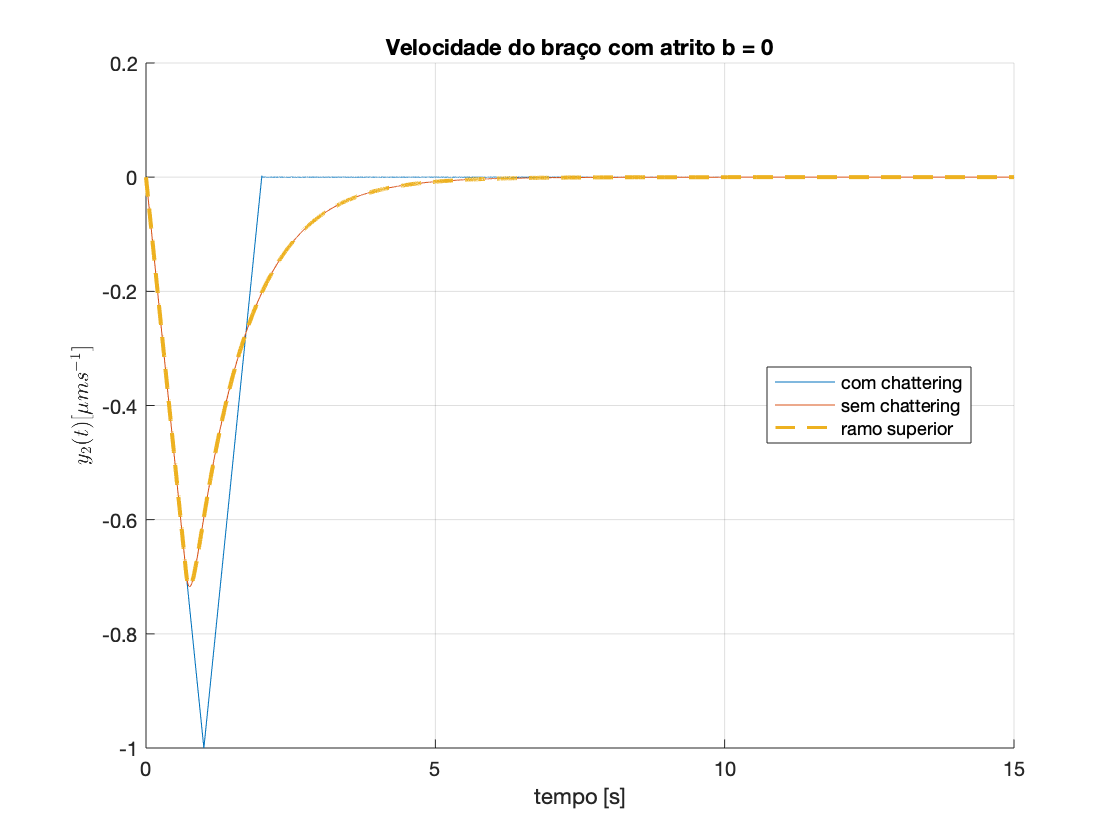


figure();clf; hold on;
plot(y2_8);
plot(y2_10);
plot(y2_10_lzo, '--', 'LineWidth', 1.5); grid on;
title('Velocidade do braço com atrito b = 0')
ylabel('$y_2(t) [\mu ms^{-1}]$','interpreter', 'latex');
xlabel('tempo [s]');
legend('com chattering','sem chattering', 'ramo superior', 'Location', 'best');

Exibem-se então os gráficos que comparam as duas arquitecturas de cadeia fechada estudadas. 

Conforme seria de esperar verifica-se que a nova arquitectura, a que anula o *chattering*, demora mais tempo a atingir o zero partindo da posição inicial em comparação com a arquitectura que apresenta *chattering.* Este resultado já foi explicado na alínea anterior, porém constata-se agora a sua efectiva ocorrência. Sobreposto a estes dois gráficos está um terceiro que corresponde à nova arquitectura mas com uma alteração ligeira que corresponde à extensão da zona linear do sinal de controlo u para actuar sobre qualquer valor de $x$ que entre em $f(x)$ (implementada no Subsys). Com esta mudança não verificamos alterações em relação ao caso normal, isto porque o valor de yl definido (yl = 1) faz com que o estado inicial se localize sobre a zona linear (de onde já não sai). É também o mesmo ponto de partida no caso alterado dado que só existe a zona linear (limitada pela saturação contudo).

## (12) - Comportamento em condições com atrito b=0.025

Para esta situação procura-se testar a resposta de ambas as arquitecturas de malha fechada com a imposição de atrito (b=0025).

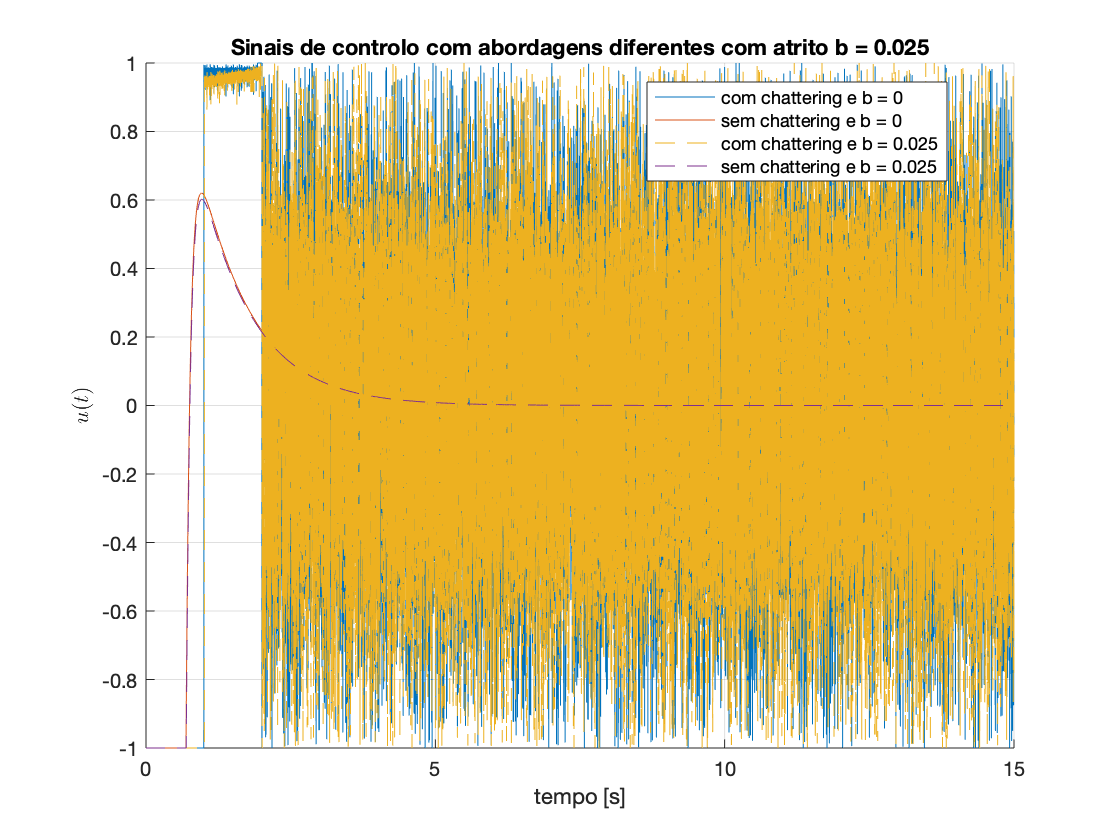

s = set_system(0.025);
s.T = 8;

c.q = 8; % question
signal.y = sim('disco_rigido');
u_8a = signal.y.u8;
y1_8a = timeseries(signal.y.y.Data(:,1), signal.y.y.Time);
y2_8a = timeseries(signal.y.y.Data(:,2), signal.y.y.Time);

c.q = 10; % question
signal.y = sim('disco_rigido');
u_10a = signal.y.u10;
y1_10a = timeseries(signal.y.y.Data(:,1), signal.y.y.Time);
y2_10a = timeseries(signal.y.y.Data(:,2), signal.y.y.Time);

figure();clf; hold on;
plot(u_8); plot(u_10); plot(u_8a,'--'); plot(u_10a, '--'); grid on;
title('Sinais de controlo com abordagens diferentes com atrito b = 0.025')
ylabel('$u(t)$','interpreter', 'latex');
xlabel('tempo [s]');
legend('com chattering e b = 0','sem chattering e b = 0','com chattering e b = 0.025','sem chattering e b = 0.025','Location', 'best');

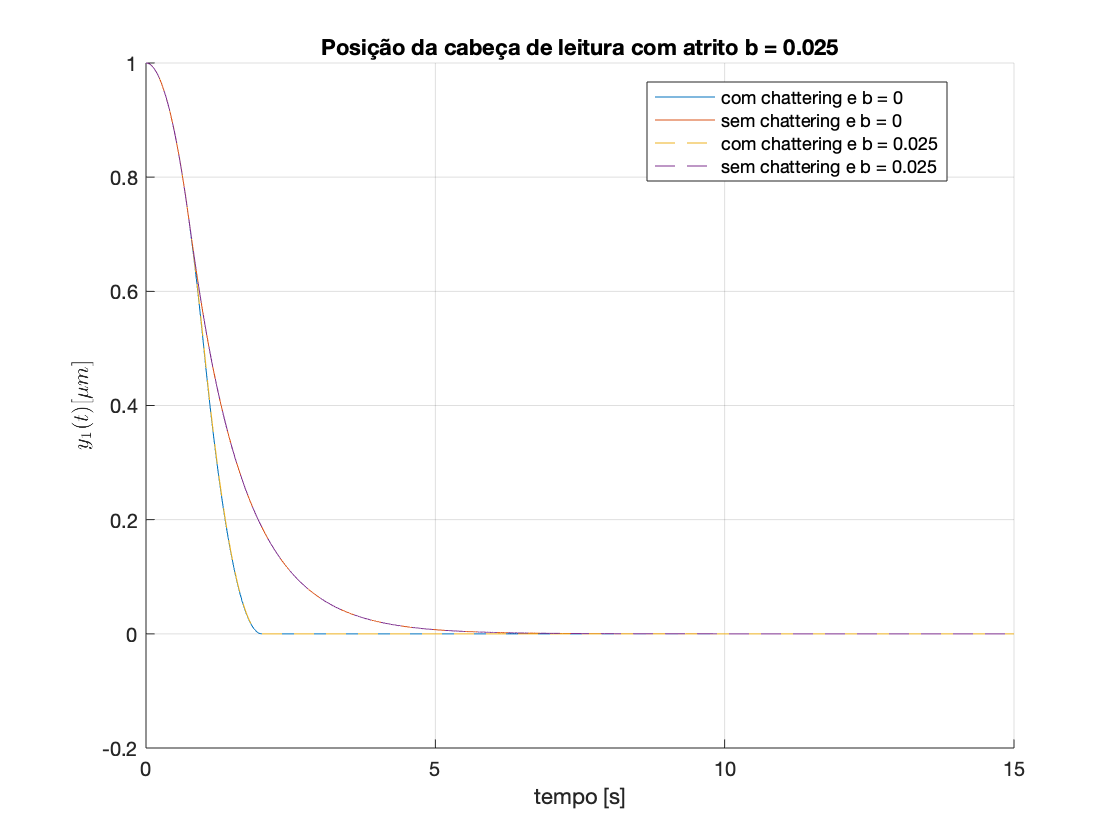


figure();clf; hold on;
plot(y1_8); plot(y1_10); plot(y1_8a,'--'); plot(y1_10,'--'); grid on;
title('Posição da cabeça de leitura com atrito b = 0.025')
ylabel('$y_1(t) [\mu m]$','interpreter', 'latex');
xlabel('tempo [s]');
legend('com chattering e b = 0','sem chattering e b = 0','com chattering e b = 0.025','sem chattering e b = 0.025','Location', 'best');

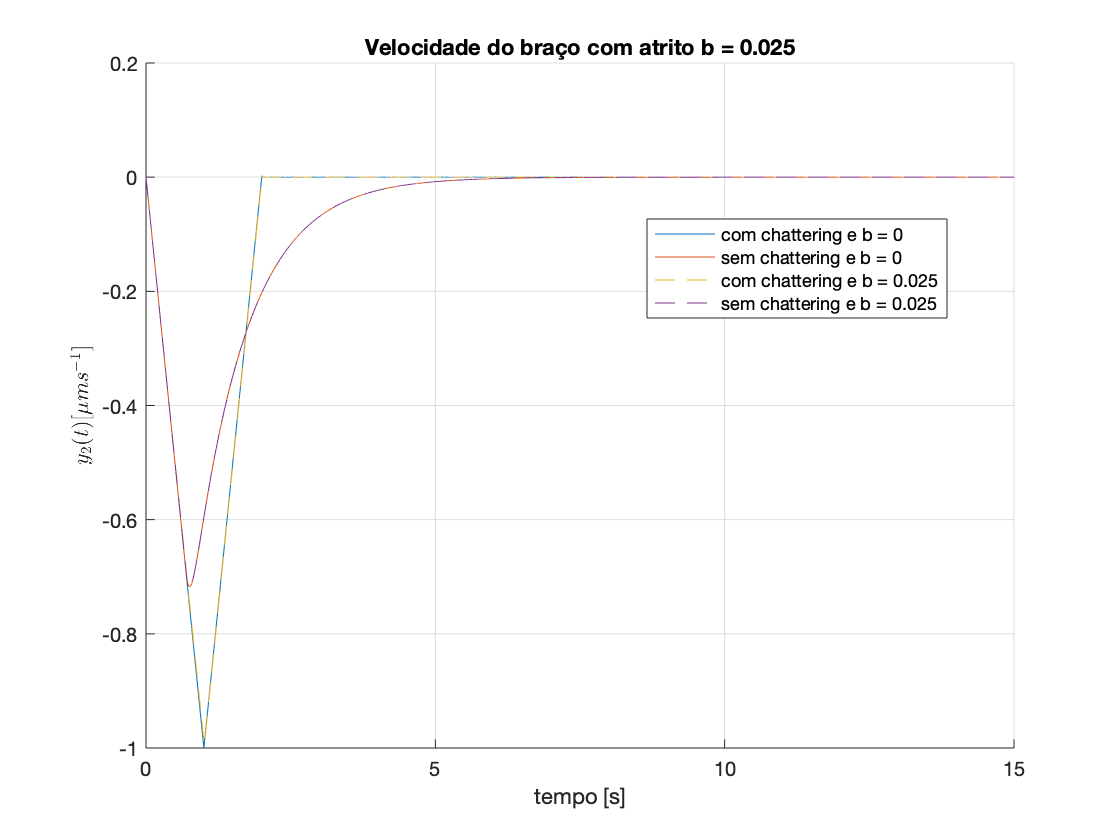


figure();clf;  hold on;
plot(y2_8); plot(y2_10);plot(y2_8a,'--'); plot(y2_10,'--'); grid on;
title('Velocidade do braço com atrito b = 0.025')
ylabel('$y_2(t) [\mu ms^{-1}]$','interpreter', 'latex');
xlabel('tempo [s]');
legend('com chattering e b = 0','sem chattering e b = 0','com chattering e b = 0.025','sem chattering e b = 0.025','Location', 'best');

Através das figuras podemos observar que ambas as arquitecturas de malha fechada contornam o efeito do atrito e terminam na posição desejada, contrastando com o sistema de malha aberta que não é capaz de eliminar esta perturbação como já foi visto anteriormente. É obviamente um factor que traz implicações a nível de robustez, pois uma arquitectura que é capaz de remover o efeito do atrito é muito mais relevante para uma implementação real em comparação com outra que não consegue fazer eliminar o seu efeito.

## (13) - Seguimento de sinais constantes por troços e sequências de rampas.

Numa última instância durante a realização do trabalho, sujeitou-se o último sistema estudado a uma referência não nula. Por outras palavras, introduziu-se como referência sinais constantes por troços ou rampas. Primeiramente, a aplicação de um sinal constante por troços permite destacar a evolução do sistema consoante a distância a que a cabeça de leitura se encontra da referência, tendo uma aproximação mais cautelosa à medida que esta diminui. Por outro lado, a aplicação de um sinal constante por rampas permite concluir facilmente que o braço está sempre em movimento e está menos tempo coincidente com o sinal de referência.

c.q = 10; % question
c.lz = 0;

% Troços
c.ref = steady_signal([1 6 7 7 10 3.5 1.5 2 4 8],[1.1 -1 2 0 -4 -7 -6.5 -7 -4 0], s.X0(1));
signal.y = sim('disco_rigido', 'Stoptime', 'c.ref.Time(end)');
u_10s = signal.y.u10;
y1_10s = timeseries(signal.y.y.Data(:,1), signal.y.y.Time);
y2_10s = timeseries(signal.y.y.Data(:,2), signal.y.y.Time);
u_ref_s = c.ref;

% Rampas
c.ref = ramps_signal([3 5 8 6 4 7 7 10],[0.8 -1 1 -0.5 1 2.5 -0.2 -0.5], s.X0(1));
signal.y = sim('disco_rigido', 'Stoptime', 'c.ref.Time(end)');
u_10r = signal.y.u10;
y1_10r = timeseries(signal.y.y.Data(:,1), signal.y.y.Time);
y2_10r = timeseries(signal.y.y.Data(:,2), signal.y.y.Time);
u_ref_r = c.ref;

As funções auxilares (steady_signal e ramps_signal) encontram-se explicadas nos anexos.

Numa comparação mais direta entre as duas situações, o sinal de entrada u(t), é menos atribulado quando a referência é por rampas, visto que à uma maior contiudidade face a um sinal de refência em que a derivada no tempo entre transições tende para infinito.

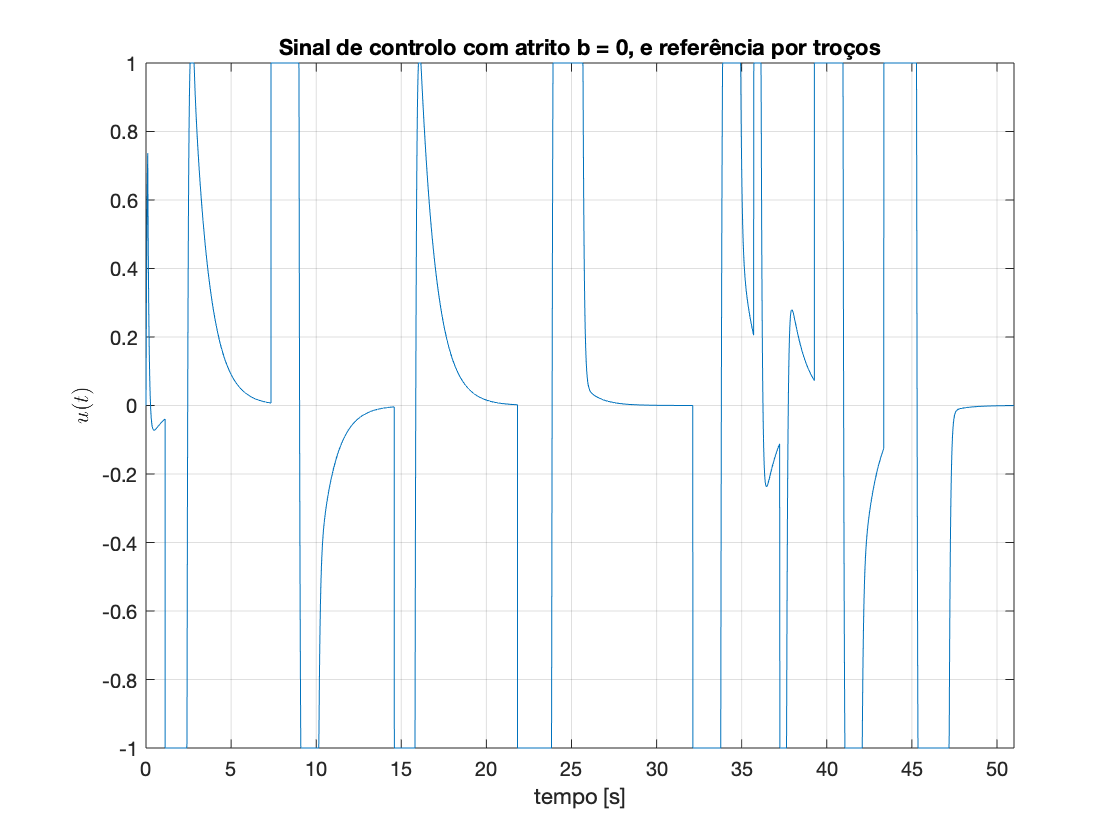

figure();clf;   %referência troços
plot(u_10s); grid on;
title('Sinal de controlo com atrito b = 0, e referência por troços')
ylabel('$u(t)$','interpreter', 'latex');
xlabel('tempo [s]');
xlim([0 c.ref.Time(end)]);

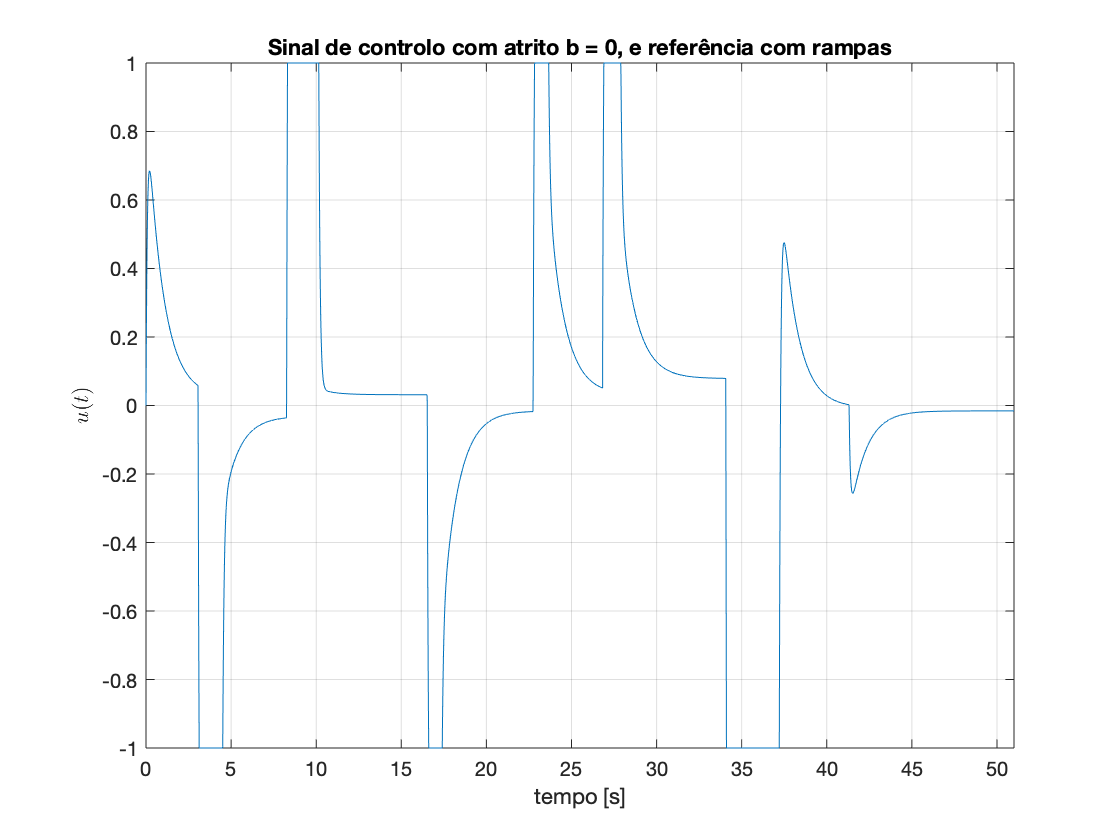


figure();clf;   %referência rampas
plot(u_10r); grid on;
title('Sinal de controlo com atrito b = 0, e referência com rampas')
ylabel('$u(t)$','interpreter', 'latex');
xlabel('tempo [s]');
xlim([0 c.ref.Time(end)]);

Relativamente à posição da cabeça de leitura, a vantagem de um sinal constante por troços prende-se num paragem momentânea da referência, o que permite ao sistema aproximar-se muito próximo do pretendido mais rapidamente.

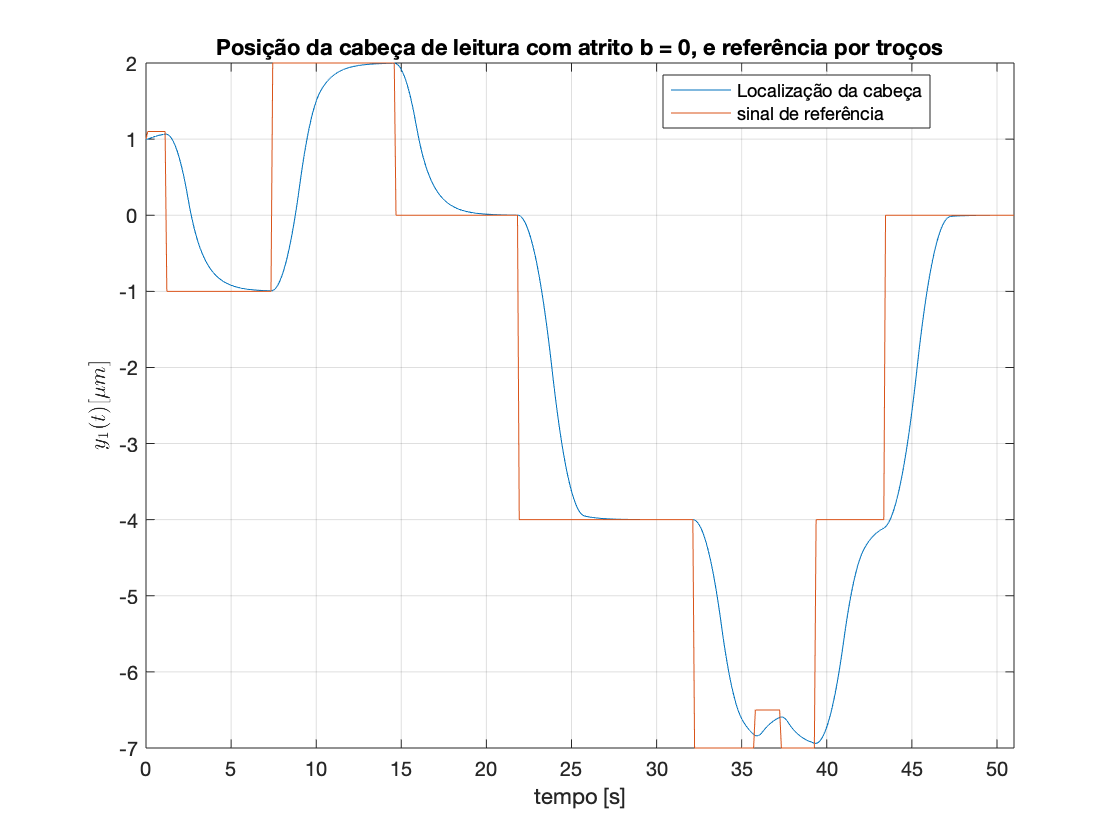

figure();clf;   % posição troços
p1 = plot(y1_10s); hold on;
p2 = plot(u_ref_s); grid on;
title('Posição da cabeça de leitura com atrito b = 0, e referência por troços')
ylabel('$y_1(t) [\mu m]$','interpreter', 'latex');
xlabel('tempo [s]');
legend([p1 p2] , {'Localização da cabeça','sinal de referência'},'Location', 'best');
xlim([0 c.ref.Time(end)])

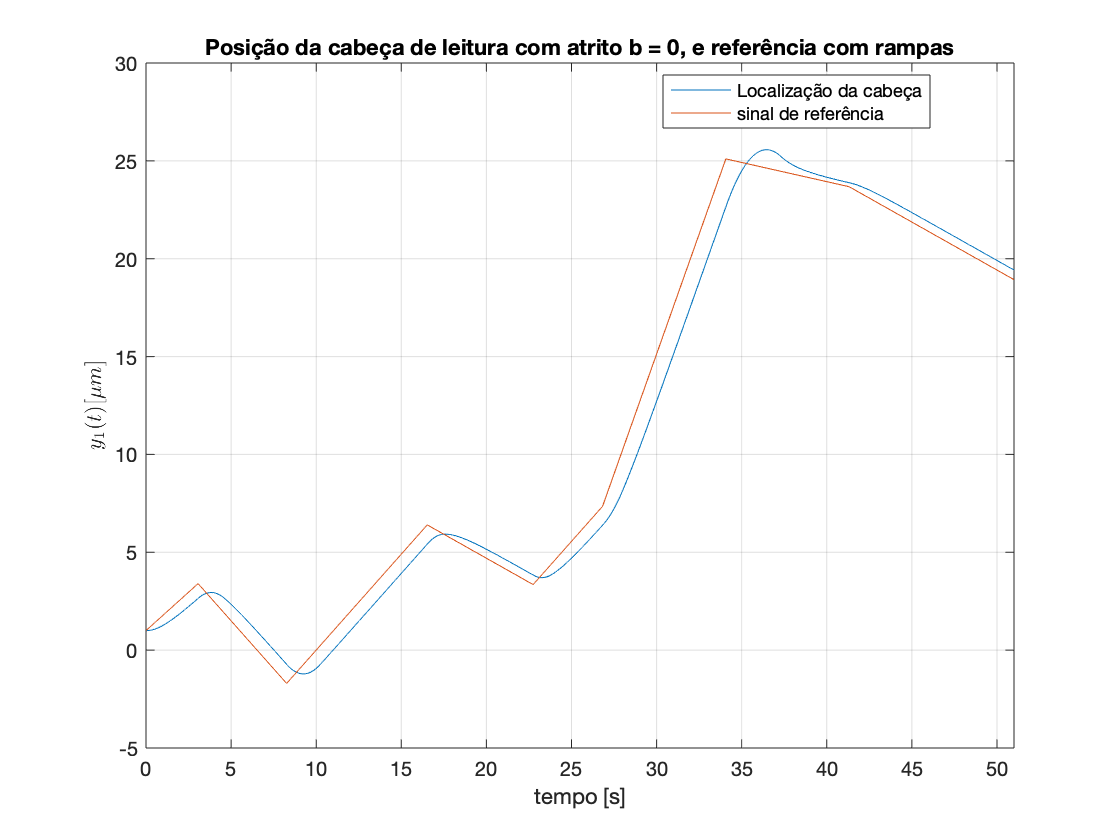


figure();clf;   %poisação rampas
p1 = plot(y1_10r); hold on;
p2 = plot(u_ref_r); grid on;
title('Posição da cabeça de leitura com atrito b = 0, e referência com rampas')
ylabel('$y_1(t) [\mu m]$','interpreter', 'latex');
xlabel('tempo [s]');
legend([p1 p2] , {'Localização da cabeça','sinal de referência'},'Location', 'best');
xlim([0 c.ref.Time(end)]);

No caso de um sinal contínuo por rampas, a posição da cabeça de leitura vai variar de uma maneira linear para distânicas à referência pequenas, ou seja a sua evolução temporal aproxima-se da evolução do sinal de referência deslocada no tempo.

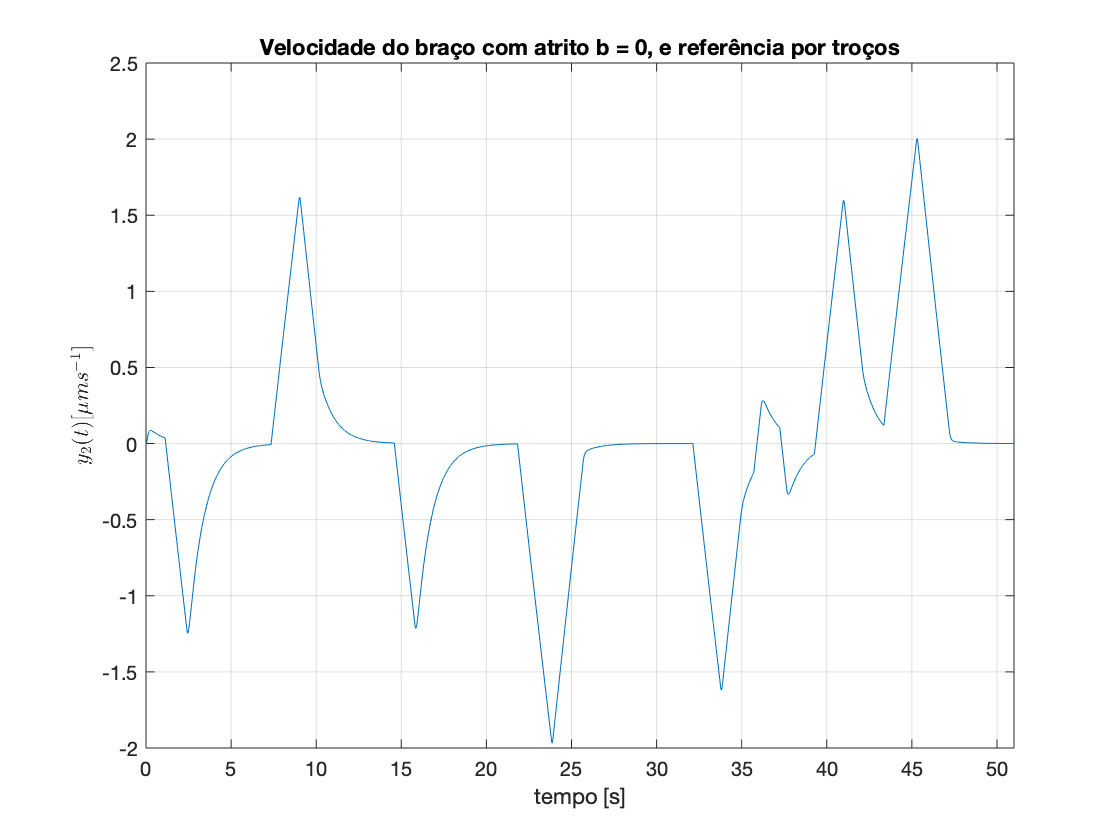

figure();clf;   %velocidade rampas
plot(y2_10s);  grid on;
title('Velocidade do braço com atrito b = 0, e referência por troços')
ylabel('$y_2(t) [\mu ms^{-1}]$','interpreter', 'latex');
xlabel('tempo [s]');
xlim([0 c.ref.Time(end)]);

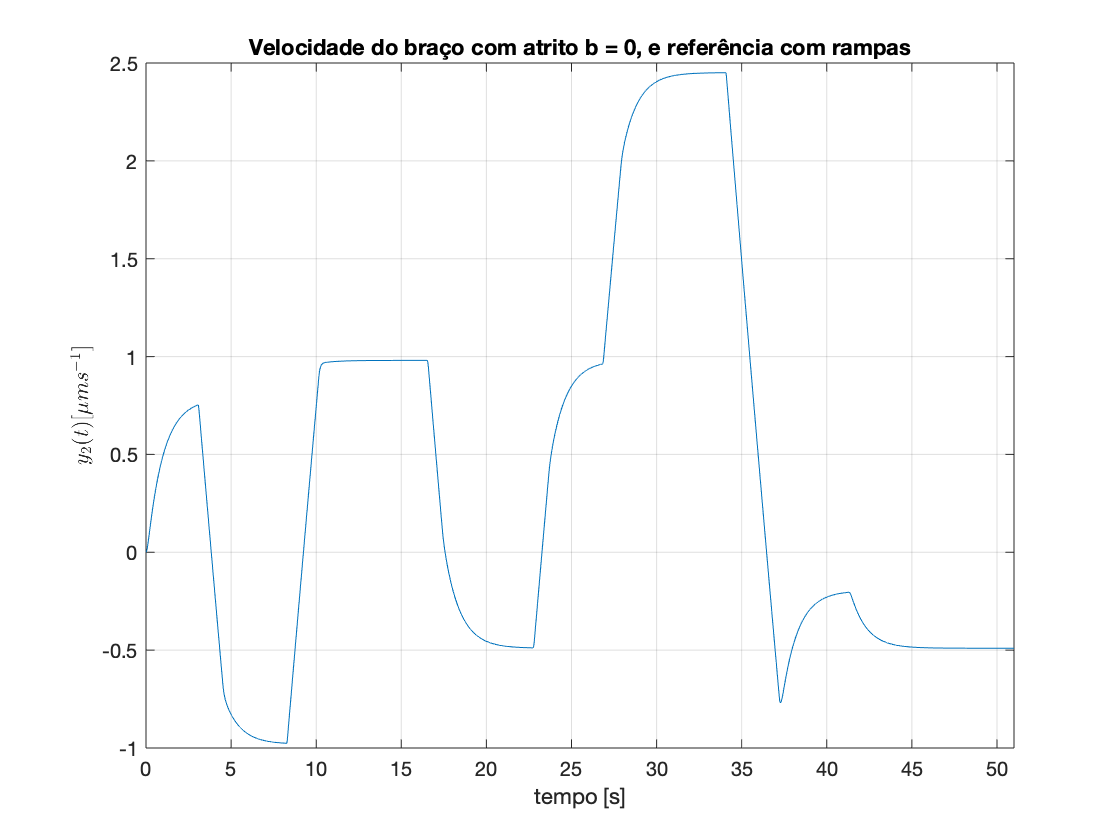



figure();clf;   %   velocidade troços
plot(y2_10r);  grid on;
title('Velocidade do braço com atrito b = 0, e referência com rampas')
ylabel('$y_2(t) [\mu ms^{-1}]$','interpreter', 'latex');
xlabel('tempo [s]');
xlim([0 c.ref.Time(end)])

Por último, através da comparação dos gráficos de velocidade do braço, o sistema submetido a sinais por troços pode ter descanso em alguns momentos, situação que não acontece numa situação de variação de posição em regime linear. Desta forma é possível concluir que para rápidas transições é mais fiável um uso de sinais por troços, porém um sistema de variação linear é preferível numa utilização base visto ser mais suave. Nota que o sistema com chattering, tornar-se-ia melhor num seguimento a sinais compostos por rampas, pois permitiria uma deslocação temporal entre o sinal de referência e a posição de braço menores.

## Anexos

type("alpha_bounds.m")  % check  and readjust alpha limits


function alpha = alpha_bounds(alpha)
% case when alpha < 0 
    if alpha < 0
        alpha = 0;
        disp('ERROR: \alpha < 0 (limit), during this function \alpha = 0')
    end
end



type("beta_bounds.m")   % check  and readjust beta limits


function beta = beta_bounds(beta)
% case when beta < 0 or beta > 1
    if beta > 1
        beta = 1;
        disp('ERROR: \beta > 1 (limit), during this function \beta = 1')
    elseif beta < 0
        beta = 0;
        disp('ERROR: \beta < 0 (limit), during this function \beta = 0')
    end
end



type("u_impulse.m")     % generate prototype impulse


function y = u_impulse(t, beta)
    % tamanho do vector t, criacao do vector de imagens
    t_size = length(t);
    y = zeros(1, t_size);
    
    % verificao se beta se encontra dentro dos limites 
    beta = beta_bounds(beta);
    
    for i = 1:t_size
        if t(i) <= -(beta+1)/2 % zona 1
        	continue;
        
        elseif t(i) >= (beta+1)/2 % zona 7
        	continue;
        
        elseif -(beta+1)/2 < t(i) && t(i) <= -1/2 % zona 2
             y(i) = (2/beta^2)*t(i)^2 + ((2*beta+2)/beta^2)*t(i) + ((2*beta+1)/(2*beta^2)) + 1/2;
        
        elseif -1/2 < t(i) && t(i) <= (beta-1)/2 % zona 3
             y(i) = -(2/beta^2)*t(i)^2 + ((2*beta-2)/beta^2)*t(i) + ((2*beta-1)/(2*beta^2)) + 1/2;
        
        elseif (beta-1)/2 < t(i) && t(i) < (1-beta)/2 % zona 4
             y(i) = 1;
        
        elseif (1-beta)/2 <= t(i) && t(i) < 1/2 % zona 5
             y(i) = -(2/beta^2)*t(i)^2 + ((2-2*beta)/beta^2)*t(i) + ((2*beta-1)/(2*beta^2)) + 1/2;
        
        elsei

type("u_generator.m")   % generate a sequence of two opposite prototypes impulse


function [v_t, v_u] = u_generator(s)
    % parsing da string de entrada
    [T, alpha, beta, U1, U2, n1, n2] = get_signal(s);
    
    % verificao dos limites de alpha e beta 
    beta = beta_bounds(beta);
    alpha = alpha_bounds(alpha);
    
    % calculo do comprimento de u1 e u2
    T1 = T/(1+alpha);
    T2 = T - T1;
    
    % vector de tempos normalizados para u1 e u2
    v_t1 = linspace(-(beta+1)/2, (beta+1)/2, n1);
    v_t2 = linspace(-(beta+1)/2, (beta+1)/2, n2);
    
    % vector resultante da funcao de impulso para u1 e u2 (normalizado)
    v_u1 = u_impulse(v_t1, beta);
    v_u2 = u_impulse(v_t2, beta);
    
    % desnormalizacao amplitude
    v_u1 = -U1*v_u1;
    v_u2 = U2*v_u2;
    
    % desnormalizacao comprimento e posicao no tempo
    v_t1 = v_t1*((T1)/(1+beta)) + T1/2;
    v_t2 = v_t2*((T2)/(1+beta)) + T1 + T2/2;
    
    % array de tempos e amplitude final
    v_t = [v_t1 v_t2(2:end)];
    v_u = [v_u1 v_u2(2:end)];
end


type("get_signal.m")    % get parametrs of signal struct


function [T, alpha, beta, U1, U2, n1, n2] = get_signal(s)

    % get S struct parameters
    
    T=s.T; 
    alpha=s.alpha; 
    beta = s.beta; 
    U1=s.U(1); 
    U2=s.U(2); 
    n1=s.N(1); 
    n2=s.N(2);
    
end



type("fcn.mlx")         % controller auxiliar function (SIMULINK)


function y = fcn(u,yl,lz)
    % Fig5 controller
    k=[inv(yl) sqrt(2/yl)];
    if u <= yl || lz == 1
        y = k(1)/k(2)*u;
    else
        y = sign(u)*(sqrt(2*abs(u))-inv(k(2)));
    end
y = u;


type("steady_signal.m") % generates one sinal with several steps from period and constante values


function y = steady_signal(t,m,xo)
    % generates one sinal with several steps from period and constante values.
    
    % t and m vectores have to be the same size;
    if( length(t) ~= length(m) )
        aux = min(length(t),length(m));
        t=t(1:aux);
        m=m(1:aux);
    end

    t = abs(t); % t must be positive
    samp_t = 0.1;   % max period resolution   
    y(1:round(sum(t)/samp_t+1)) = xo;   % declare signal
    aux = t;    j=1;    % auxiliar variables    
    
    for i = 1:sum(t)/samp_t    % ouput sinal increment
        
        % period limit
        if aux(j) <= 0          
            j=j+1;
        end
        aux(j) = aux(j) - samp_t;

        y(i+1)=m(j);      % step            
    end
    
    y = timeseries(y',linspace(0,sum(t)+1,sum(t)/samp_t+1));    % return a sinal with multiple steps
    
end



type("ramps_signal.m")  % generates one sinal with several ramps from period and slope values


function y = ramps_signal(t,m,xo)
    % generates one sinal with several ramps from period and slope values.
    
    % t and m vectores have to be the same size;
    if( length(t) ~= length(m) )
        aux = min(length(t),length(m));
        t=t(1:aux);
        m=m(1:aux);
    end
    
    t = abs(t); % t must be positive
    samp_t = 0.1;   % max period resolution 
    y(1:round(sum(t)/samp_t+1)) = xo;   % declare signal
    aux = t;    j=1;    % auxiliar variables
    
    for i = 1:sum(t)/samp_t    % ouput sinal increment
        
        % period limit
        if aux(j) <= 0
            j=j+1;
        end
        aux(j) = aux(j) - samp_t;
        
        y(i+1)=y(i)+(m(j)*samp_t);      % slope
    end
    
    y = timeseries(y',linspace(0,sum(t)+1,sum(t)/samp_t+1));    % return a sinal with multiple slopes
    
end



type("pergunta8.m")     % control signal u for the first closed loop architecture



% variáveis e vectores
ref = 0;
y = -2:0.01:2;
d_y = -2:0.01:2;

% meshgrid
[Y, D_Y] = meshgrid(y,d_y);

% geração da matriz de U
U = u_8(Y, D_Y, ref);

% surface plot
figure(1); clf;
surfc(Y,D_Y,U);
view(-158,46);
xlabel("$y [m]$", 'Interpreter','latex');
ylabel("$\dot{y} [ms^{-1}]$", 'Interpreter','latex');
sgtitle("$u(y, \dot{y}, $ref$)$" ,'Interpreter','latex');
colormap(jet);
shading interp;
colorbar;

% pcolor plot
figure(2); clf;
pcolor(Y, D_Y, U);
shading interp;
xlabel("$y [m]$", 'Interpreter','latex');
ylabel("$\dot{y} [ms^{-1}]$", 'Interpreter','latex');
sgtitle("$u(y, \dot{y}, $ref$)$" ,'Interpreter','latex');
colormap(gray);
colorbar;

% funcao que gera u dados y, d_y e ref
function u = u_8(y, d_y, ref)
    % subtracao de posicao a ref
    aux1 = ref - y;
    % calculo de f(x)
    aux2 = sign(aux1) .* sqrt(2*abs(aux1));
    % subtracao de velocidade
    aux3 = aux2 - d_y;
    % limitar a -1/1
    u = sign(aux3);
end



type("pergunta10.m")    % control signal u for the second closed loop architecture



% variáveis e vectores
ref = 0;
yl = 1;
y = -2:0.01:2;
d_y = -2:0.01:2;

% meshgrid
[Y, D_Y] = meshgrid(y,d_y);

% geração da matriz de U
U = u_10(Y, D_Y, ref, yl);

% surface plot
figure(1); clf;
surfc(Y,D_Y,U);
view(-136,40.35);
xlabel("$y [m]$", 'Interpreter','latex');
ylabel("$\dot{y} [ms^{-1}]$", 'Interpreter','latex');
sgtitle("$u(y, \dot{y}, $ref$)$" ,'Interpreter','latex');
colormap(jet);
shading interp;
colorbar;

% surface plot
figure(2); clf;
contourf(Y,D_Y,U);
xlabel("$y [m]$", 'Interpreter','latex');
ylabel("$\dot{y} [ms^{-1}]$", 'Interpreter','latex');
sgtitle("$u(y, \dot{y}, $ref$)$" ,'Interpreter','latex');
colormap(jet);
colorbar;



function u = u_10(y, d_y, ref, yl)
    % definicao de k1, k2
    k1 = 1/yl;
    k2 = sqrt(2*k1);
    % calculo da entrada ao subsys (subtracao de posicao)
    aux1 = ref - y;
    % f(x)
    aux2 = ((k1/k2)*aux1).*(abs(aux1) <= yl) + (sign(aux1).*(sqrt(2*abs(aux1))-1/k2)).*(abs(aux1) > yl);
    % subtracao da velocidade
    aux3 = aux2 - 